# Illustrating the ParTI method on gene expression in Cancer (RNAseq)

This script an example of how to analyze gene expression data with the ParTI method. It can be used as a template to analyze other datasets.

% Load the data into Matlab from a comma separated value (CSV) file
% The file is a purely numerical matrix, with patients as rows and genes as
% columns
geneExpression = dlmread('Data/thomas_tumors.csv', ',');
geneExpression = geneExpression'

geneExpression =     3.9716    4.6539         0    3.1865    3.9083    5.8143         0         0    1.8139    4.3700    2.0271    5.5930    0.1445    6.2369    3.2348    2.2374    3.7142    1.2740    4.6279    1.2365    1.7630    1.9999    0.4251    0.0930    0.0621    2.7220    3.9396    0.0733    2.2186    0.2627    3.1596    0.2826    0.2816    0.8562    2.8541    0.0837    3.7872    3.6641    3.6670    1.2909    3.3984    2.5435    0.2328    0.8441    3.8172    0.2856    2.7627    1.3916    2.6157    0.0344
    2.8335    4.7635         0    3.3943    3.3093    4.6570    0.2289         0    2.9169    4.1418    1.4048    5.3119    0.0831    4.6424    3.0154    2.4843    4.1512    1.0640    4.6695    2.5859    2.4351    1.4612    0.2888    2.5982    0.0829    2.8176    3.7038    0.2768    2.6650    0.5902    2.0206    1.2356    0.2808    0.3167    3.0184    0.0650    3.5224    3.6886    3.2654    1.5282    2.9289    1.7980    0.9168    0.3921    3.5368    2.1785    1.6683    1.6304  

% The file is formated as samples (i.e. patients) x genes. 
% We load gene names.
geneNames = importdata('Data/thomas_tumors_genes.csv', ',');

## We import the sample attributes, i.e. the clinical data on patients

These come in two kinds: - discrete attributes, i.e. categorical data (citizenship, gender, cancer progression grade, ...) - continuous attributes, i.e. numerical data (weight, age, tumor volume, ...) We start by loading a file with clinical attributes, both discrete and continuous.

[discrAttrNames, discrAttr] = ...
    read_enriched_csv('Data/thomas_tumors_response.csv', ',');

%where discrAttr is a matrix of patients x attributes. The names of
%the attributes are stored in discrAttrNames.

% Continuous attributes are analysed using a different statistical procedure
% than discrete attributes. We therefore load a file with vectors 'discIdcs' and 
% 'contIdcs' containing the indices of discrete and continuous attributes 
% to be considered in the study:
% load Data/CancerRNAseq/CancerRNAseq_featIdcs.mat;

% We extract continous attributes, discarding the sample ID
% (the order of the clinical records matches that of the expression data)
% contAttrNames = discrAttrNames(:,contIdcs);
% contAttr = discrAttr(:,contIdcs);
% Now we convert contAttr to a matrix of doubles
% contAttr = str2double(contAttr);

% And select the remaining discrete attributes:
% discrAttrNames = discrAttrNames(:,discIdcs);
% discrAttr = discrAttr(:,discIdcs);

## We expand the sample attributes by computing changes in GO category expression

This section is optional. It makes it possible to determine broad gene expression categories that are over-expressed in the vicinity of archetypes. This is helpful to characterize the archetypes.

[GOExpression,GONames,~,GOcat2Genes] = MakeGOMatrix(geneExpression, geneNames, ...
                {'MSigDB/CancerHallmarkGenes.txt'}, ...
                10);
% GOExpression is a matrix of patients x GO categories, and
% GONames contains the name of the GO categories.
% GOcat2Genes is a boolean matrix of genes x GO categories which
% indicates, for each category, which genes were used to compute it.
% In the next line, we expand this matrix so that it has as many columns as
% the number of continuous features (clinical + GO). Because clinical
% features are typically not directly based on specific genes, we add
% zeroes in the corresponding columns:
% GOcat2Genes=[zeros(size(GOcat2Genes,1),size(discrAttr,2)),GOcat2Genes];
% % and we expand the continuous clinical features with GO-based continuous
% % features:
% contAttrNames = [contAttrNames, GONames];
% contAttr = [contAttr, GOExpression];
contAttrNames = GONames;
contAttr = GOExpression;

## Finally, we substitute underscores '_' in variable names with spaces ' '

to prevent the characters following underscores from appearing in indice position.

discrAttrNames = regexprep(discrAttrNames, '_', ' ');
% contAttrNames = regexprep(contAttrNames, '_', ' ');


## We are now ready to perform Pareto Task Inference.

We use the Sisal algorithm (1), with up to 8 dimensions. We provide the discrete patient attributes, and ask ParTI to preliminary booleanize these attributes (0). We also pass continuous patient attributes. We pass a boolean matrix specifiying which genes each continuous feature is baesd on (to be used in the leave-one-out procedure). We specify that the enrichment analysis will be performed with a bin size of 5%. Finally, the output of the the analysis will be stored in an Excel spreadsheet, under the name 'CancerRNAseq_enrichmentAnalysis_*.csv'. 5 is PCHA

Starting to perform PCA, for big data on slow computers this may take a while...


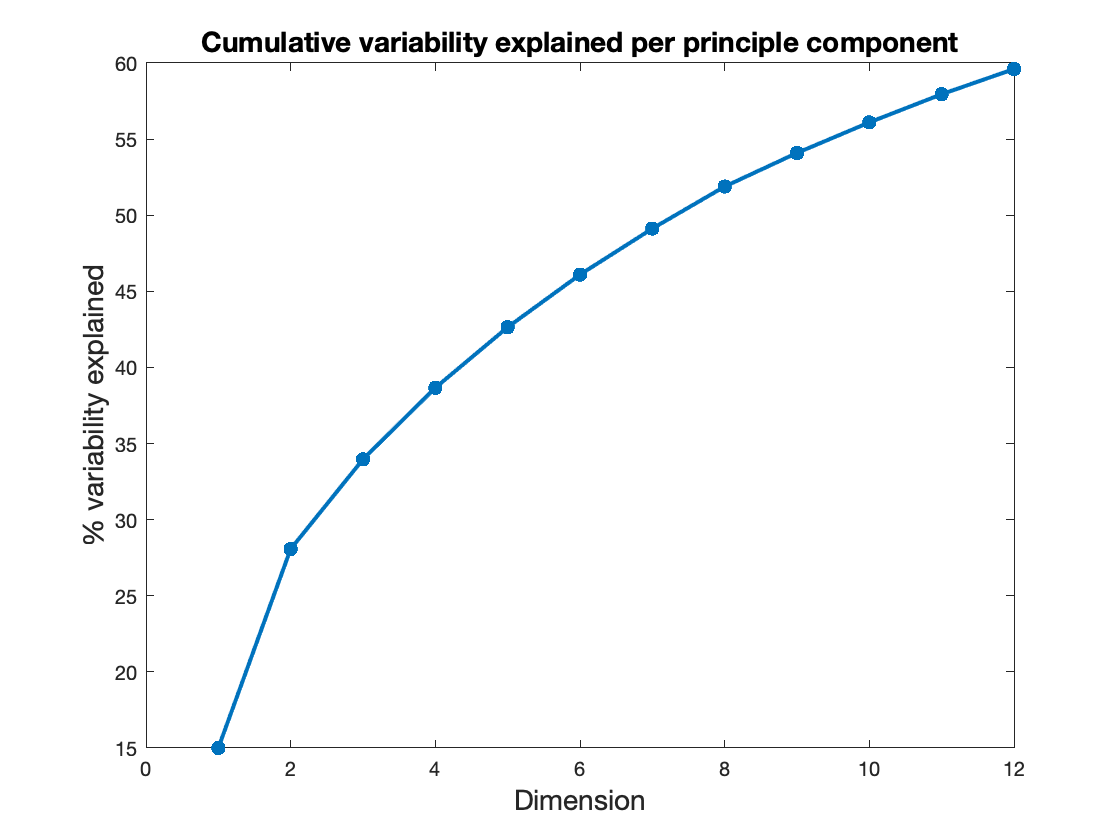

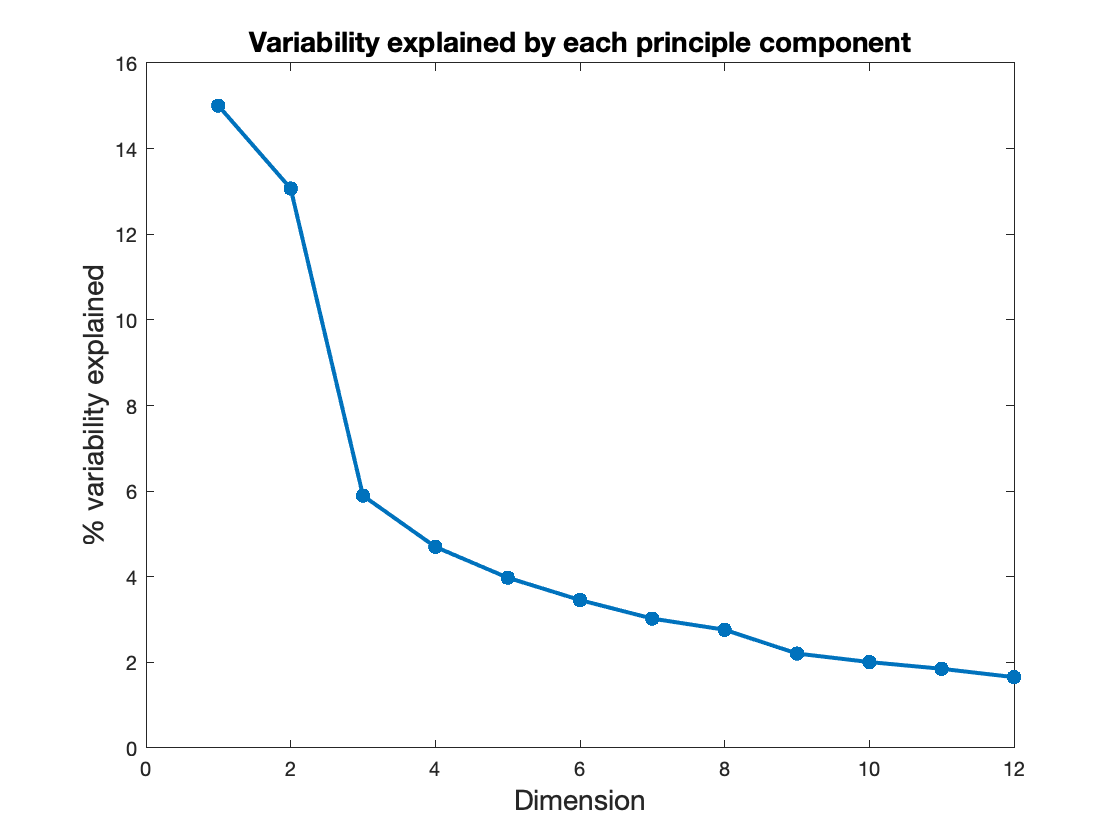

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


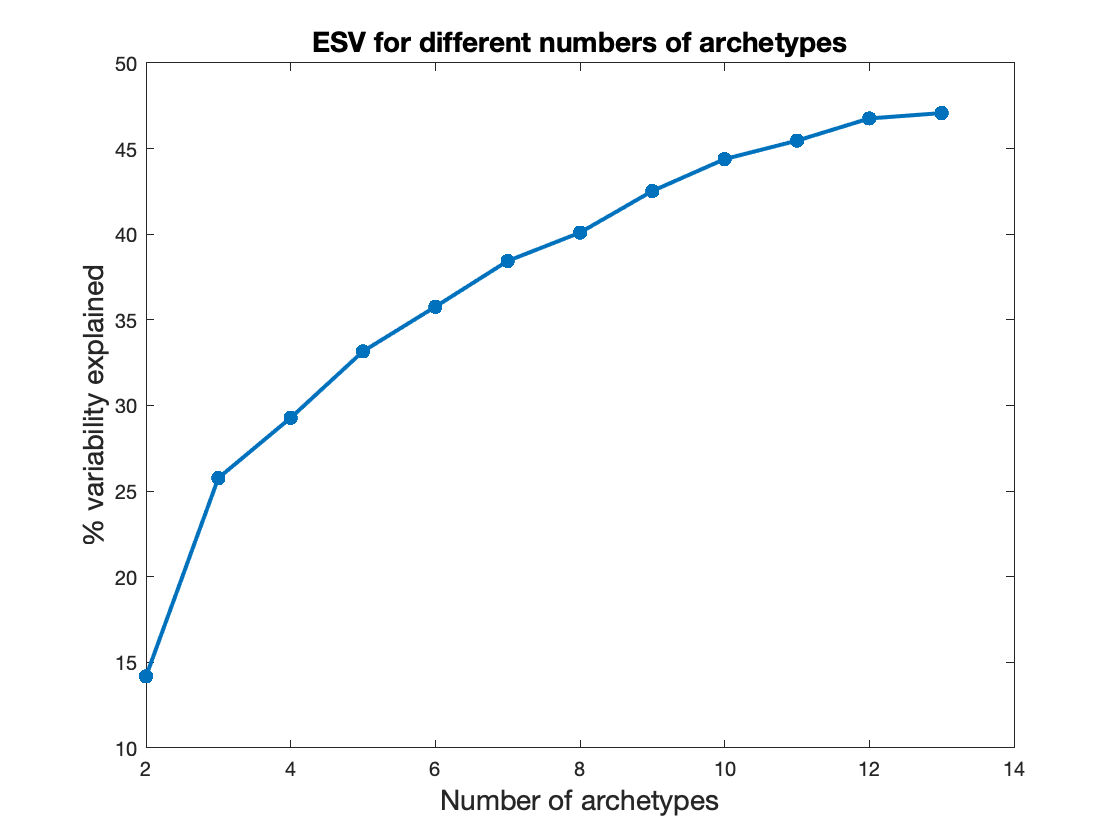

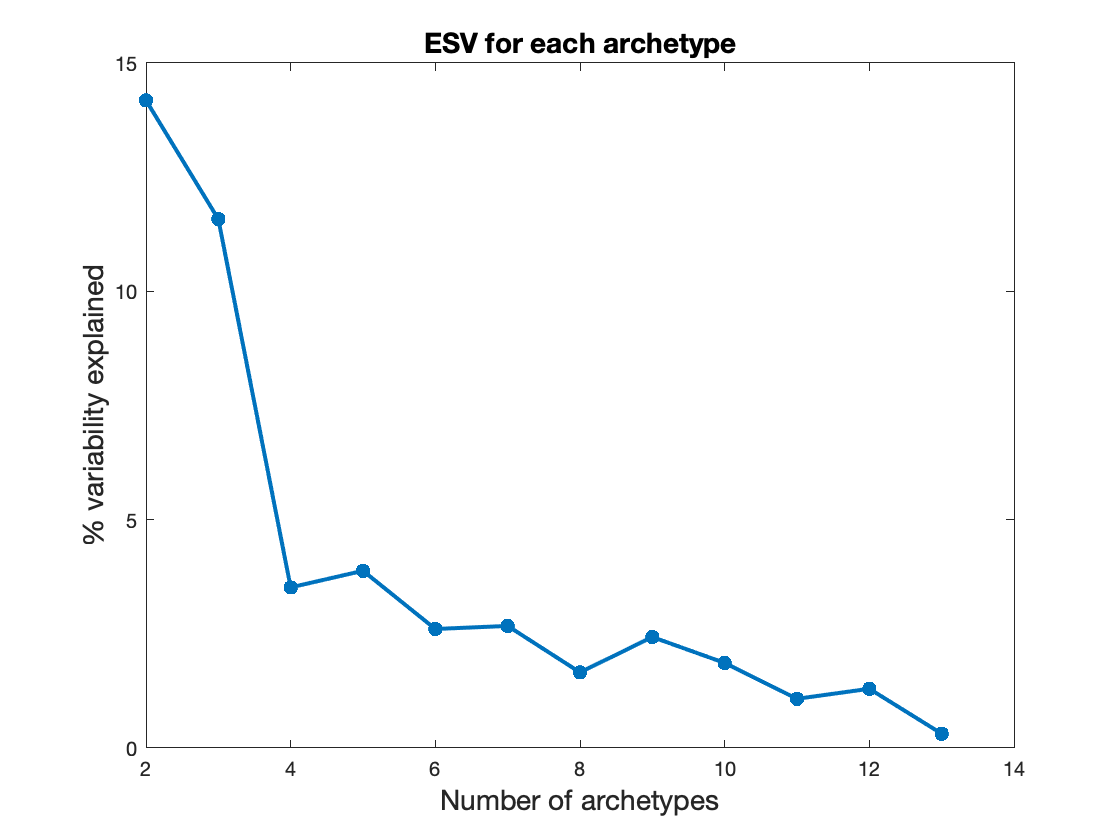

Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes


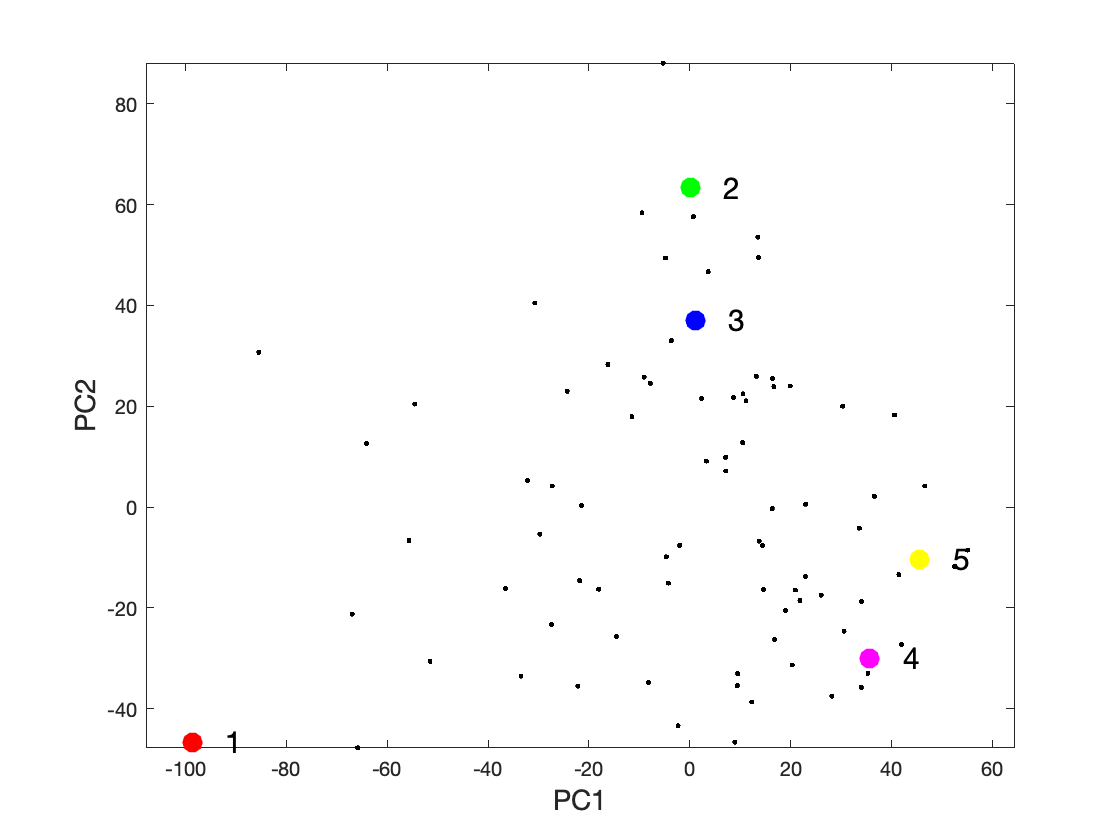

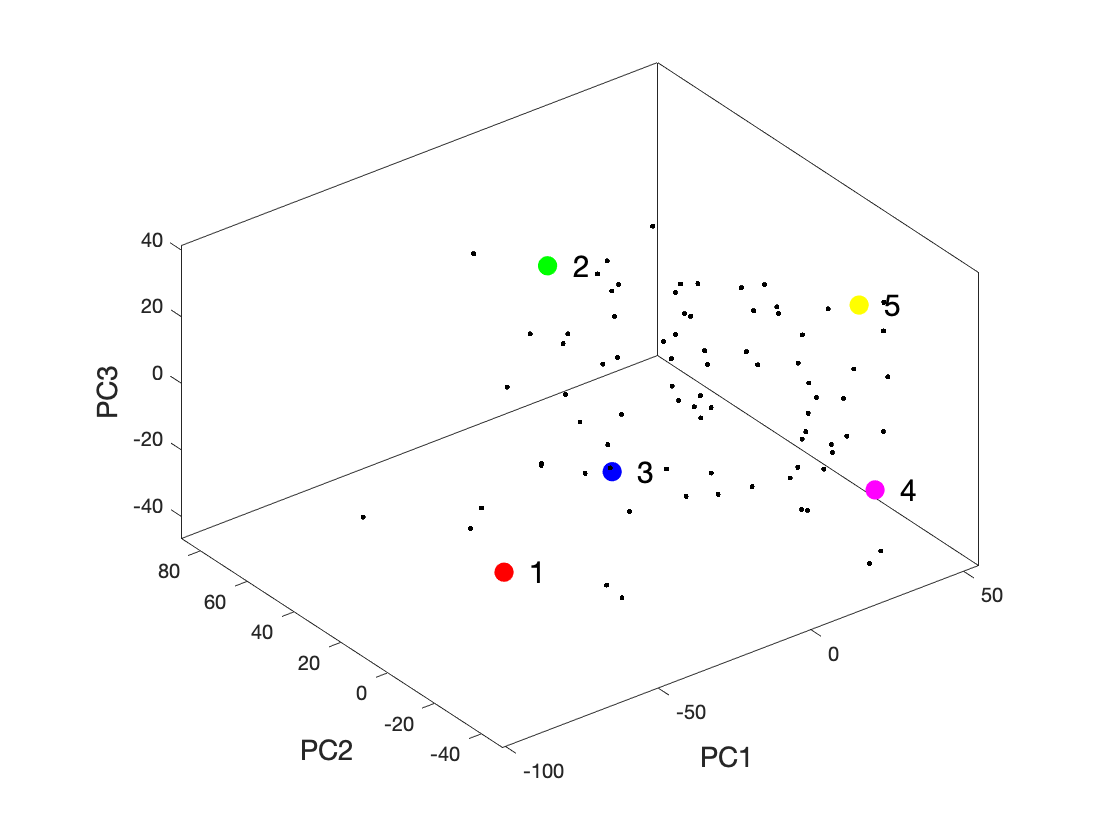

Finished sorting data points.
Your data was divided into 20 bins.


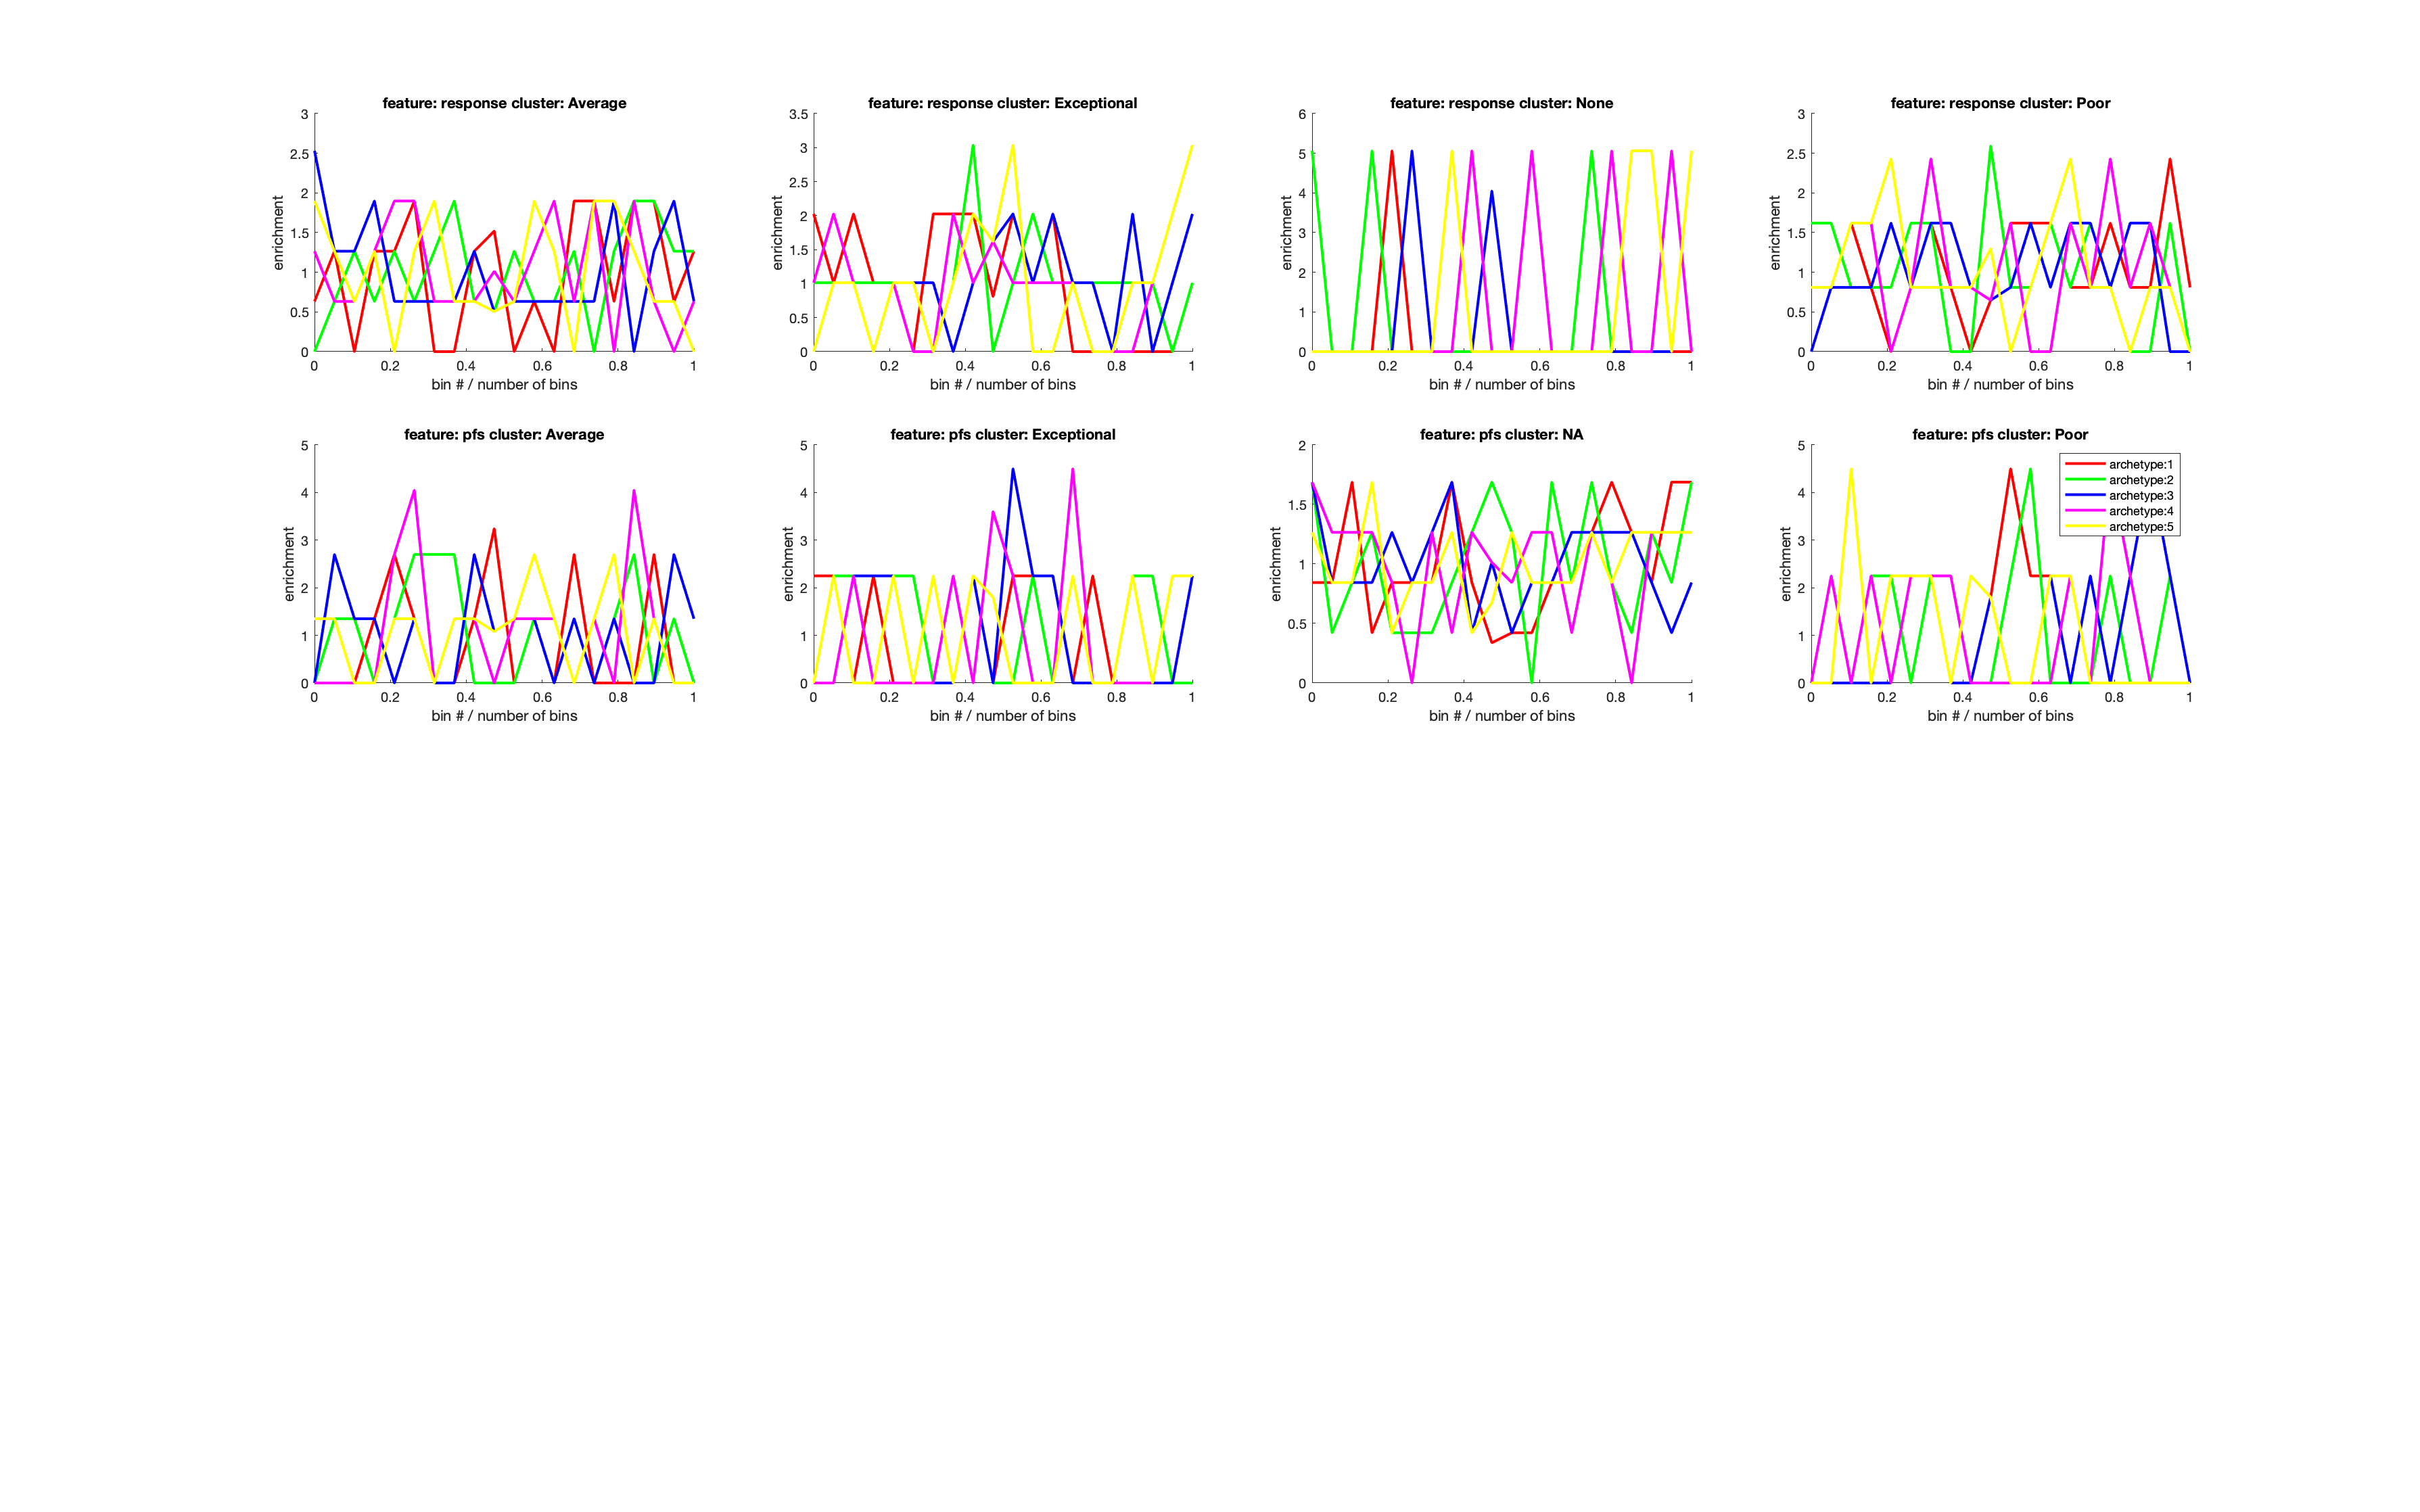

Finished computing discrete enrichments.
Finished computing continuous enrichments.
*** Wrote summary of enriched discrete features to thomas_tumors_discrete_significant.csv
*** Wrote summary of enriched continuous features to thomas_tumors_continuous_significant.csv


[arc_lite, arcFinal, pc_lite] = ParTI_lite(geneExpression, 5, 12, discrAttrNames, ...
    discrAttr, 0, contAttrNames, contAttr, [], 0.05, 'thomas_tumors');

## Finally, we perform the compete analysis, including randomization

controls and archetype error estimation.

Starting to perform PCA, for big data on slow computers this may take a while...


Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


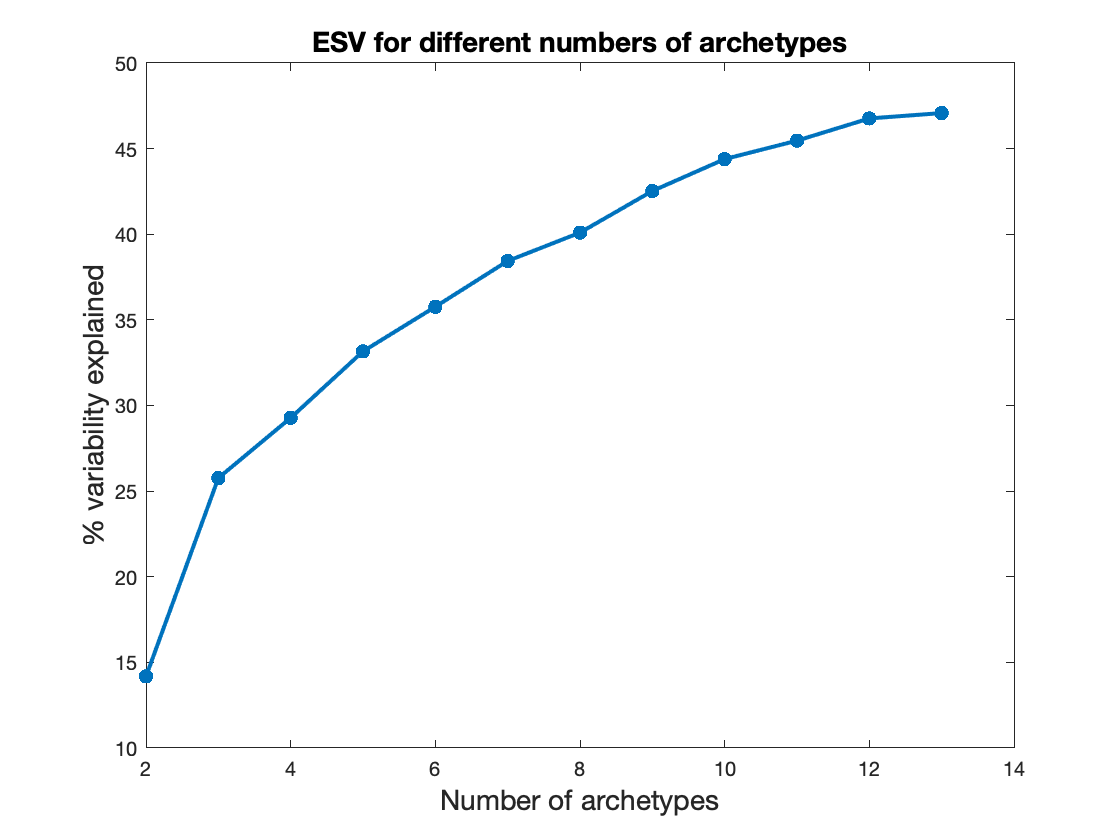

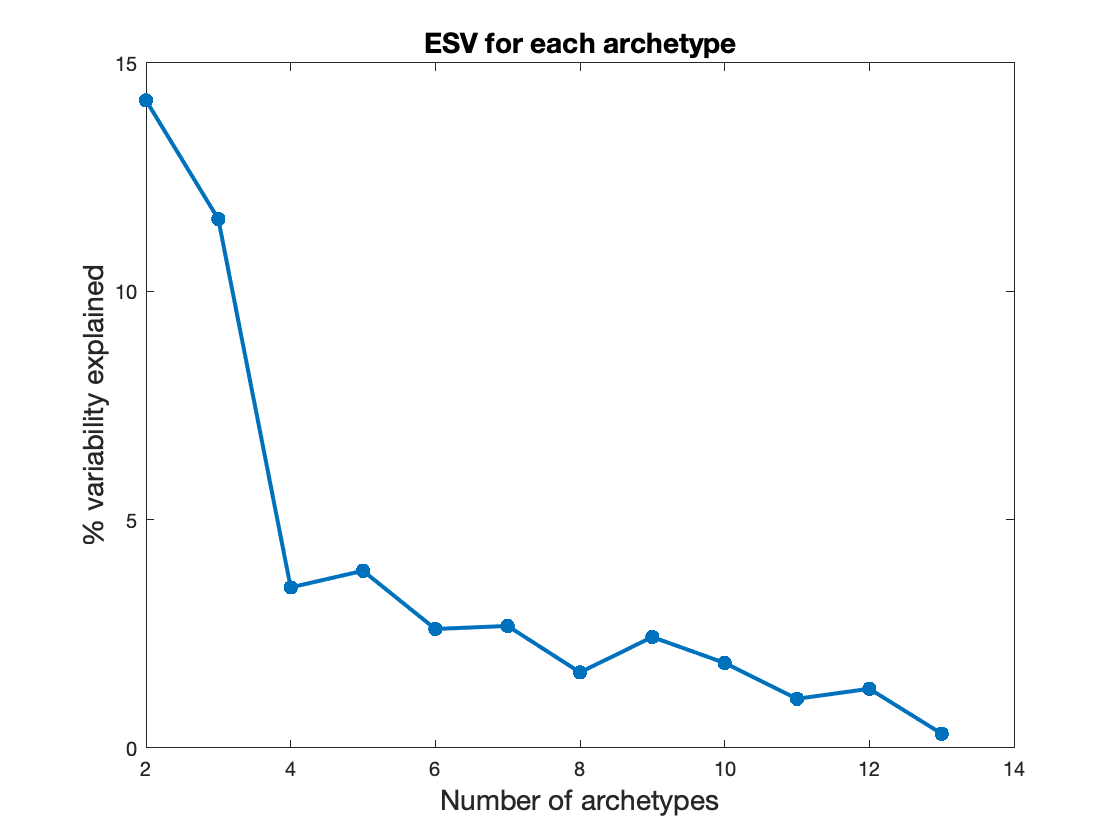

Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes
Now computing t-ratios.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
The significance of 5 archetypes has p-value of: 0.17800 
Now calculating errors on the archetypes.
10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done
100% done
finished finding the archetypes error distribution


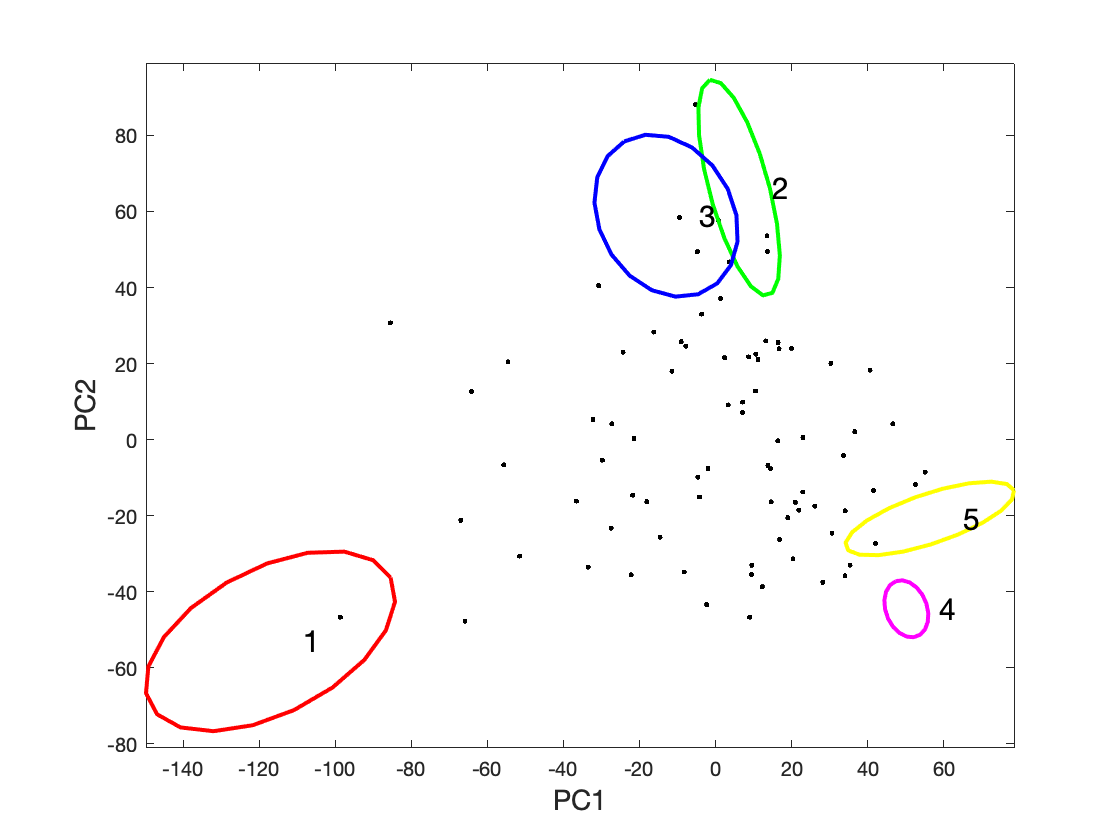

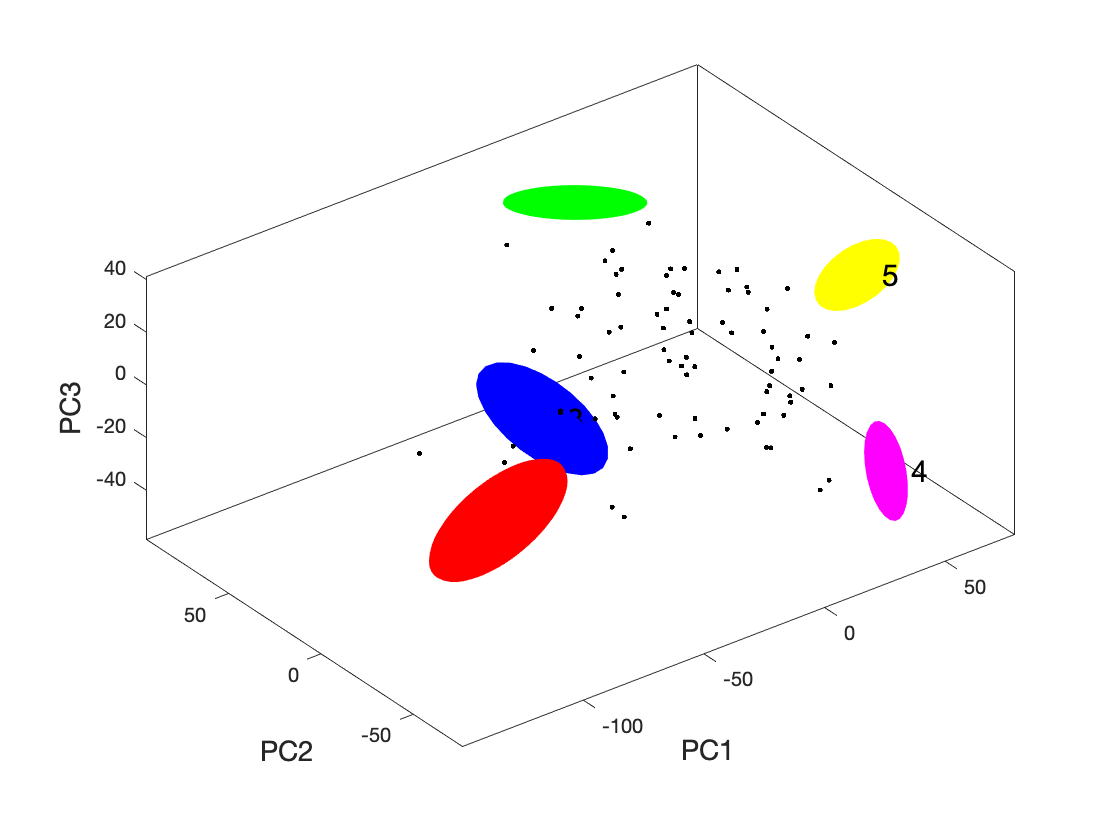

Finished sorting data points.
Your data was divided into 20 bins.


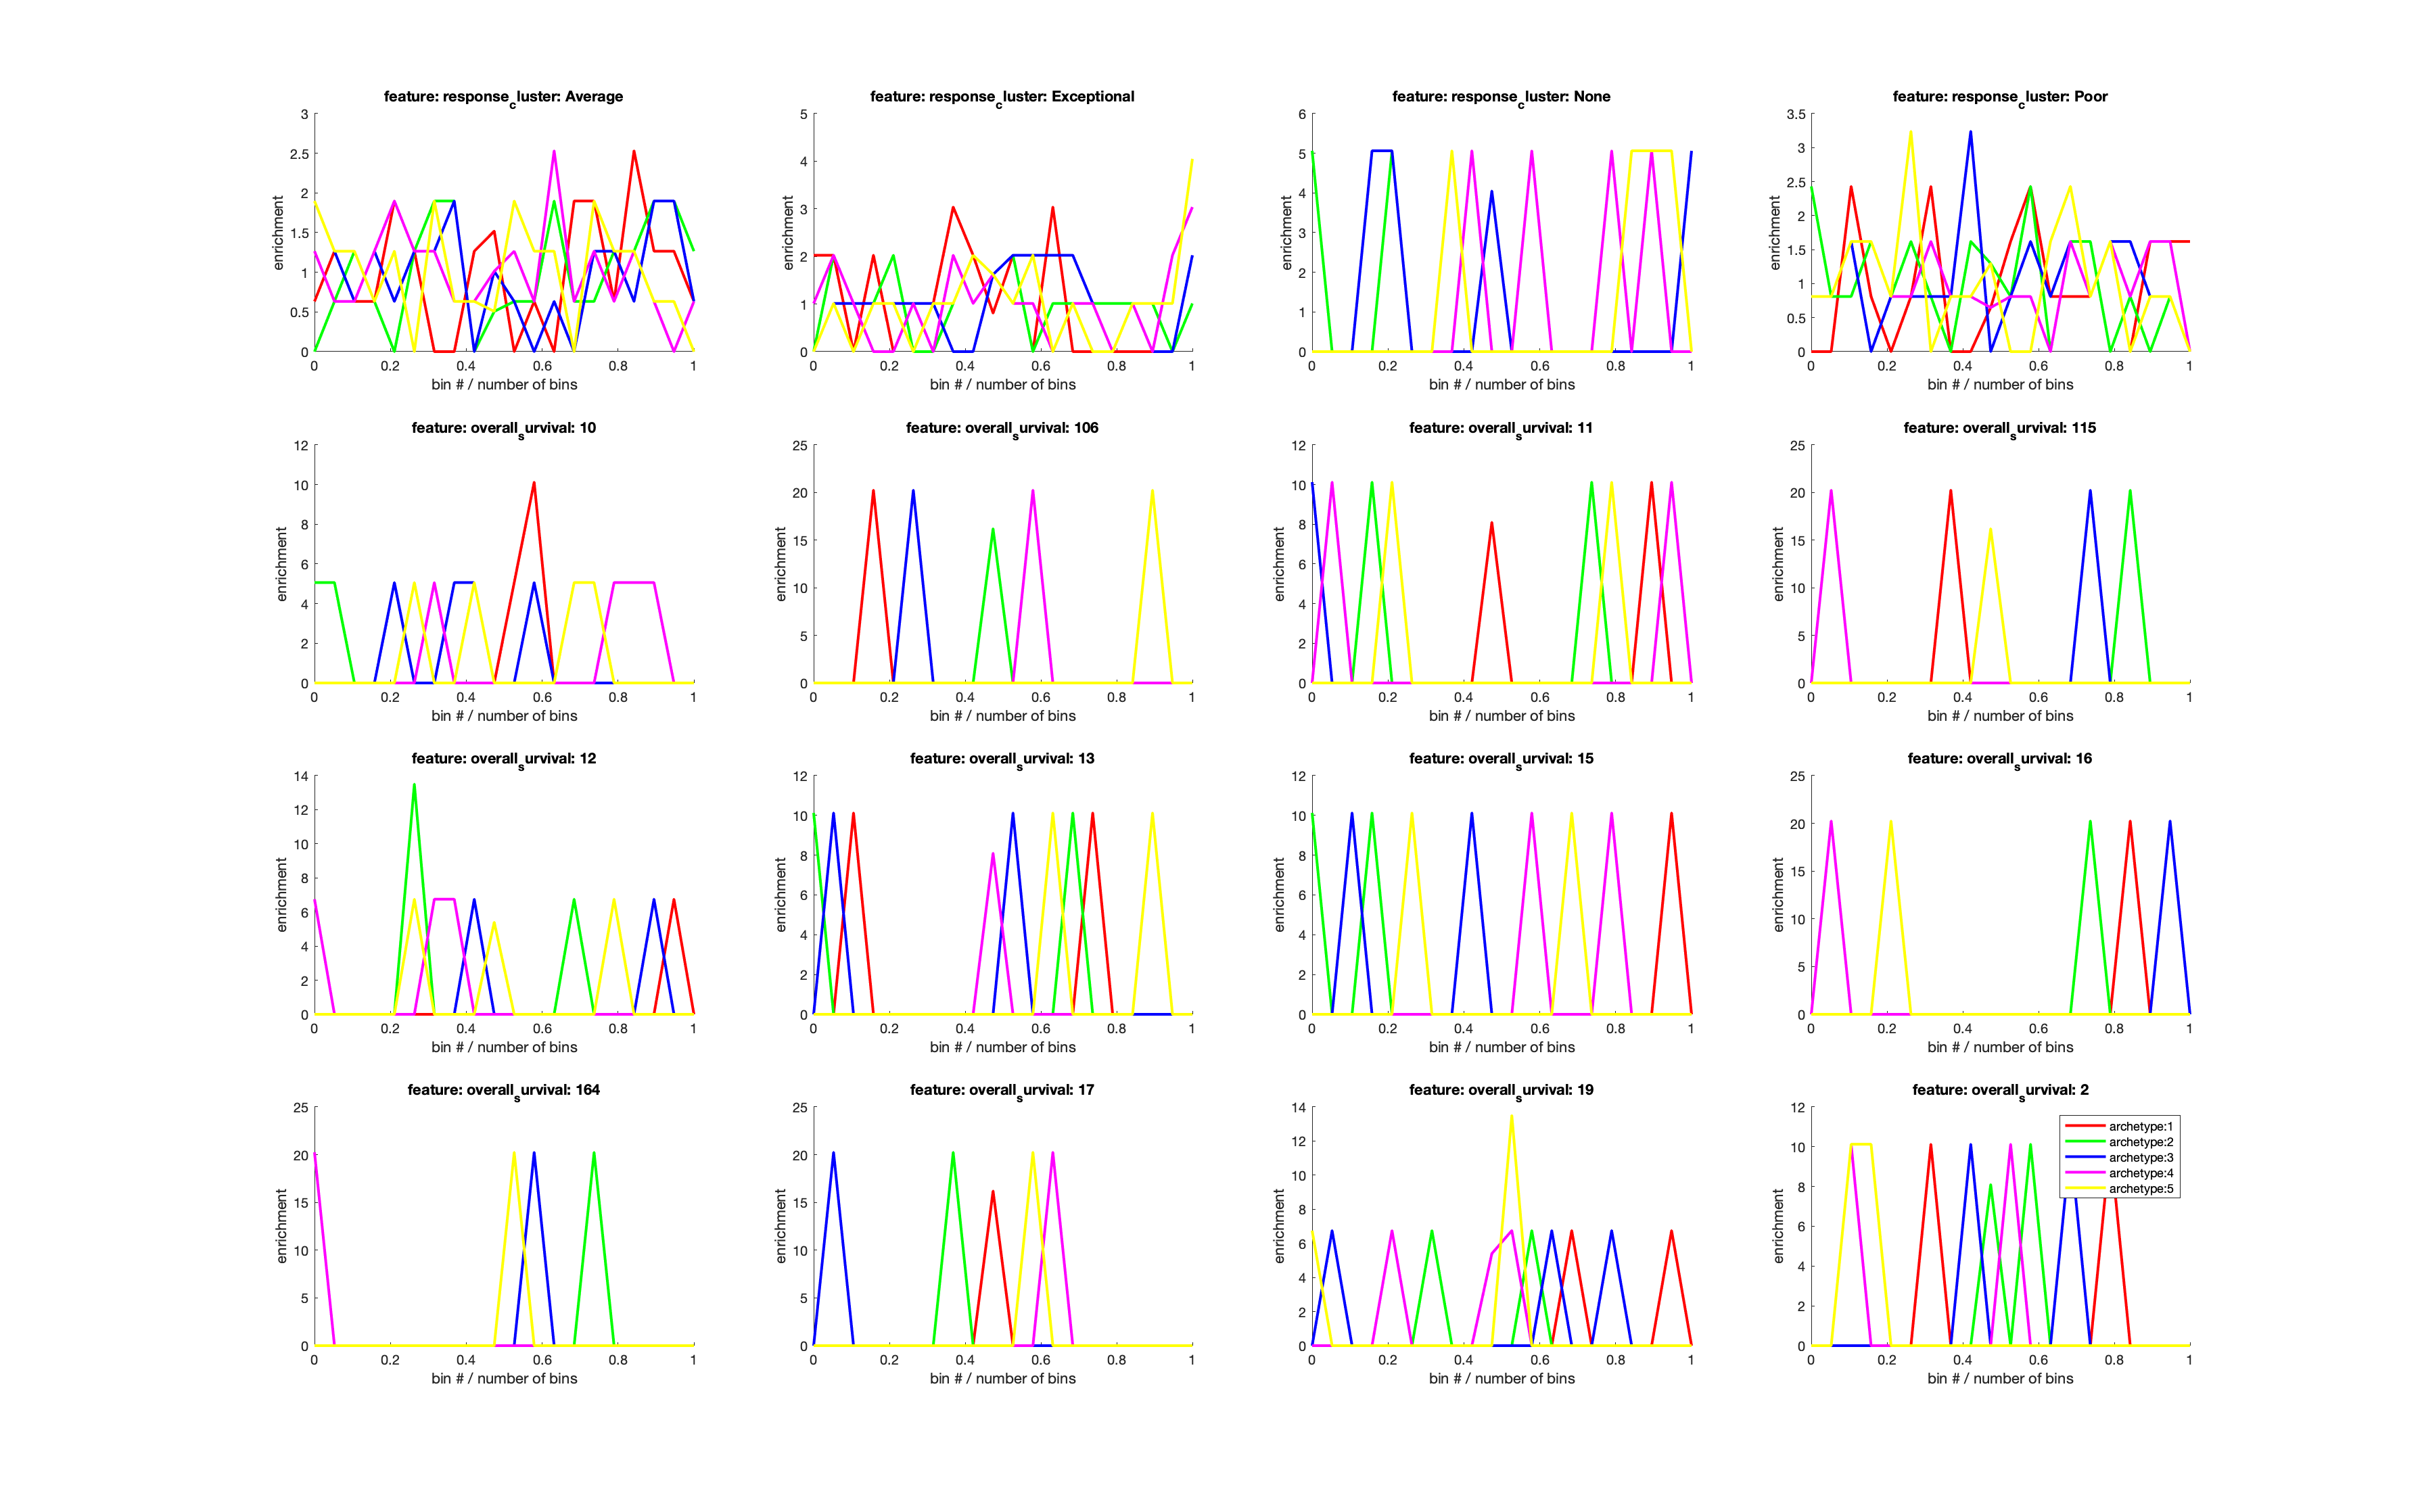

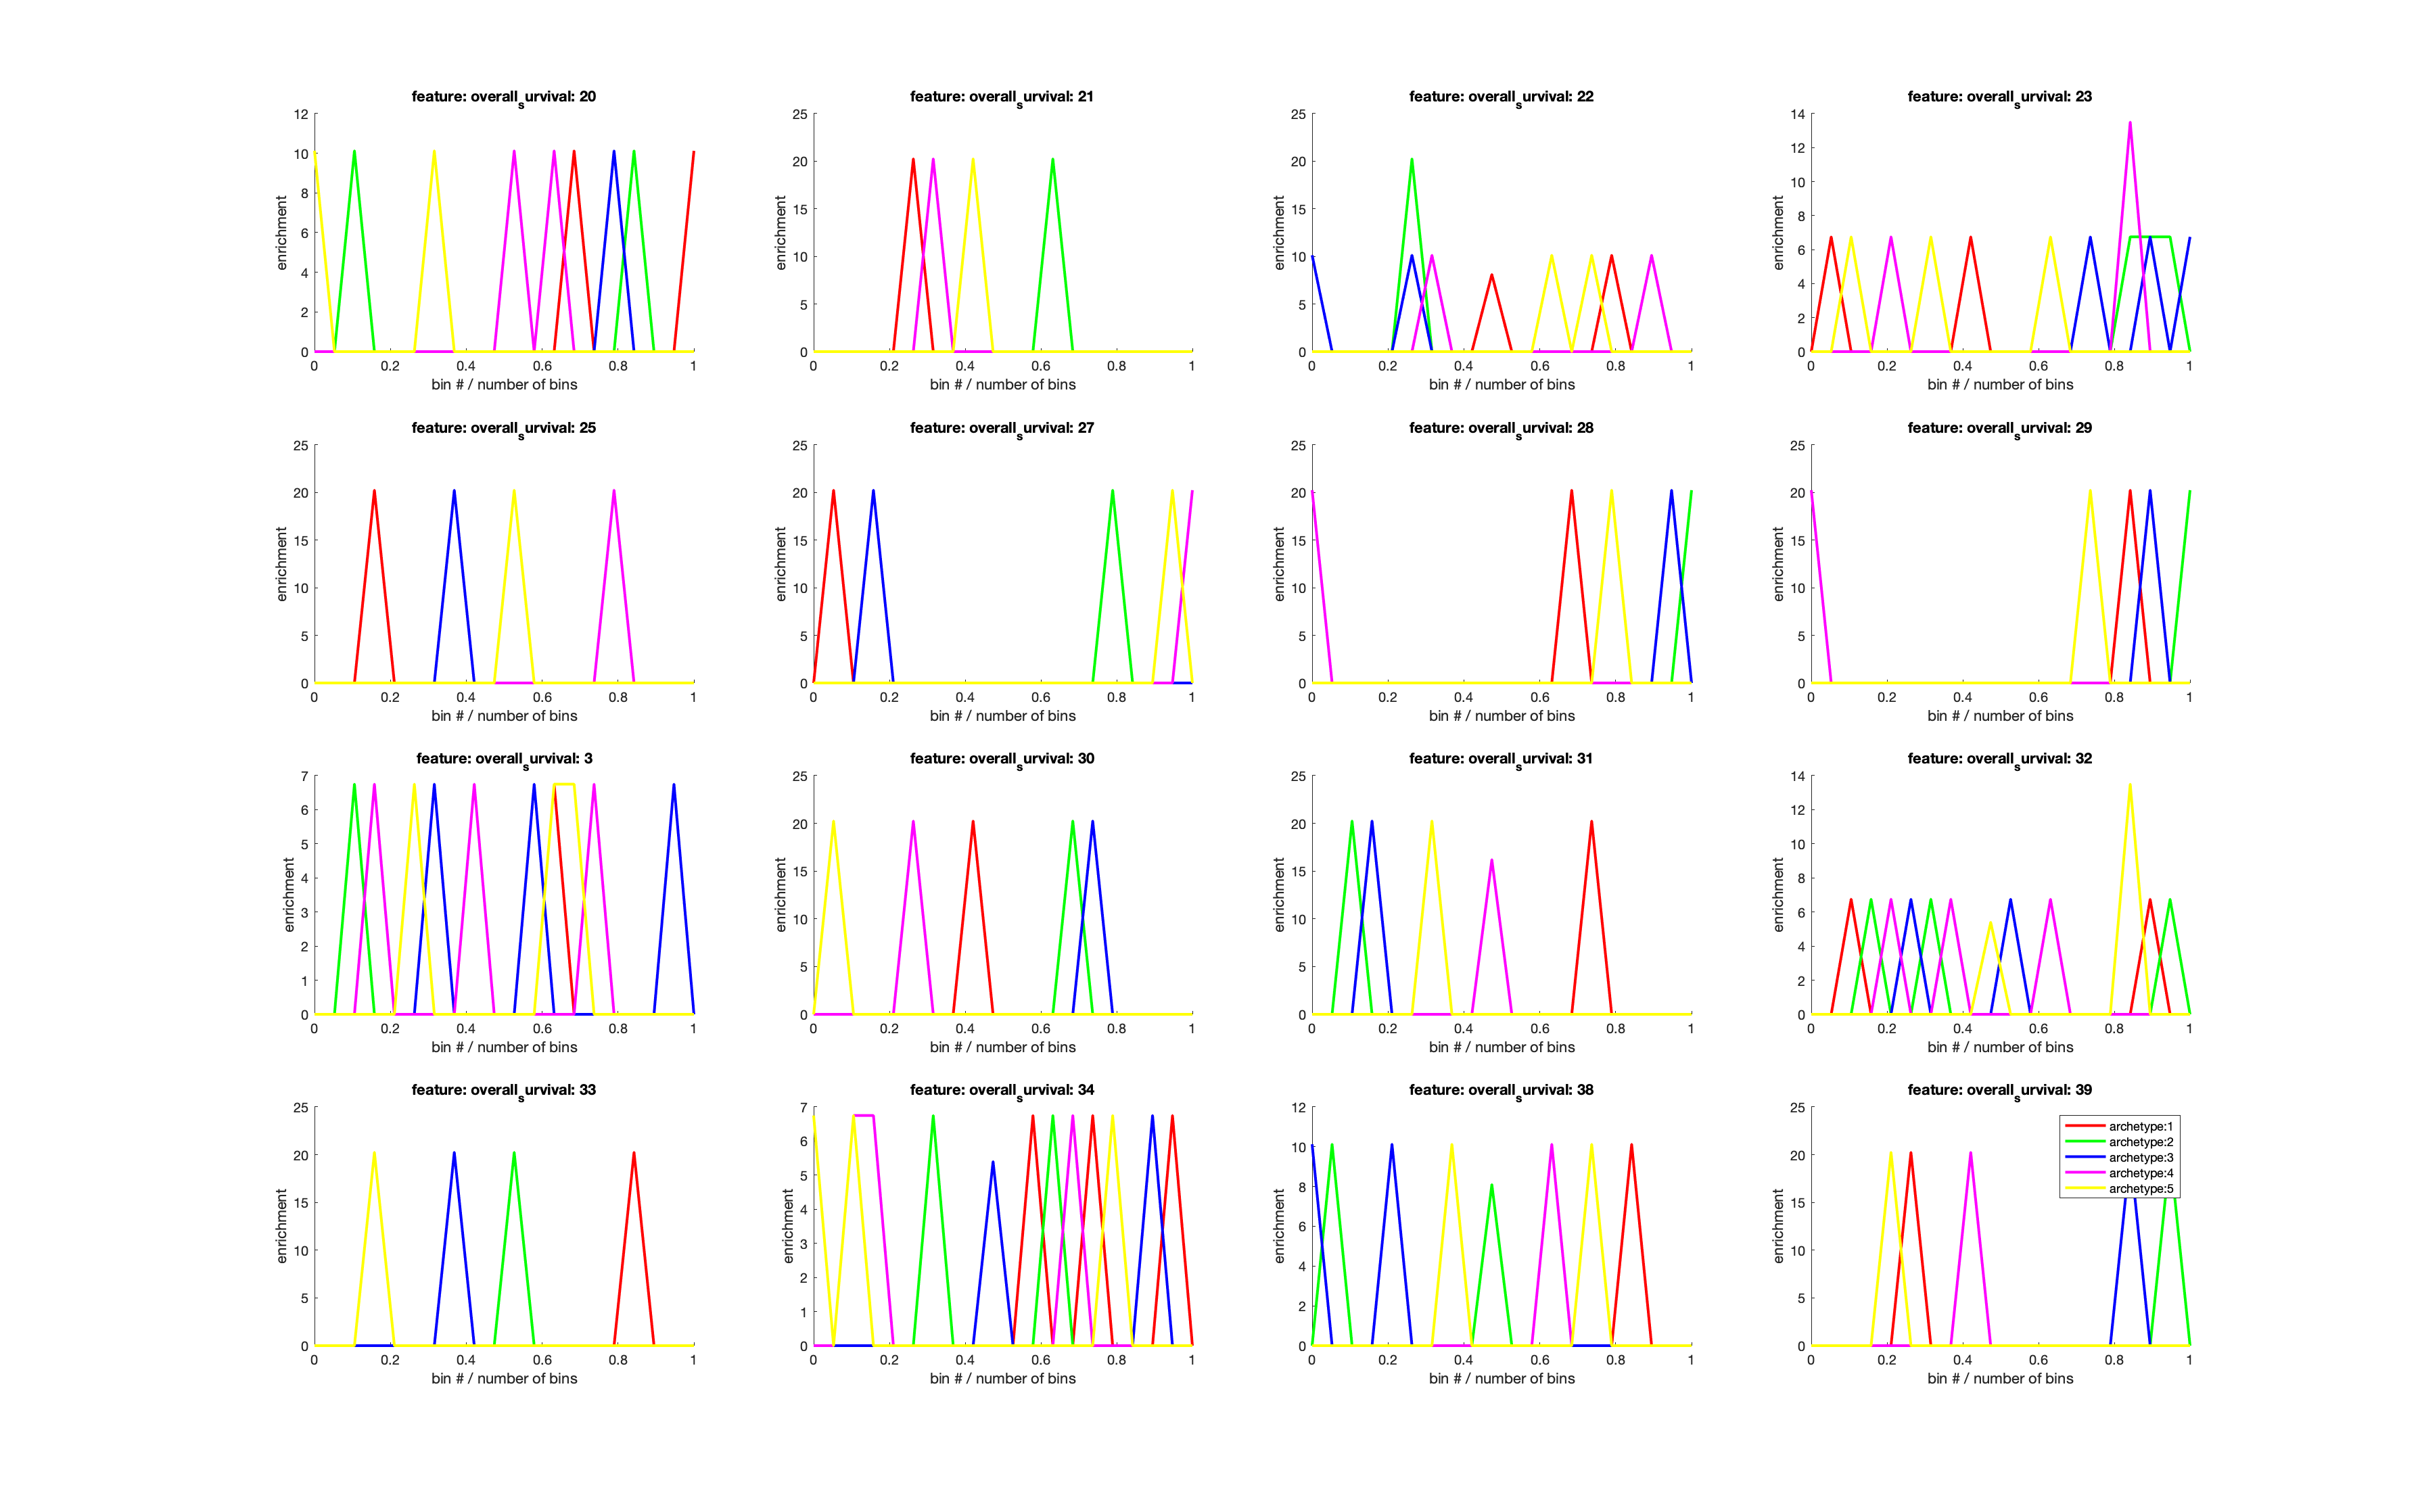

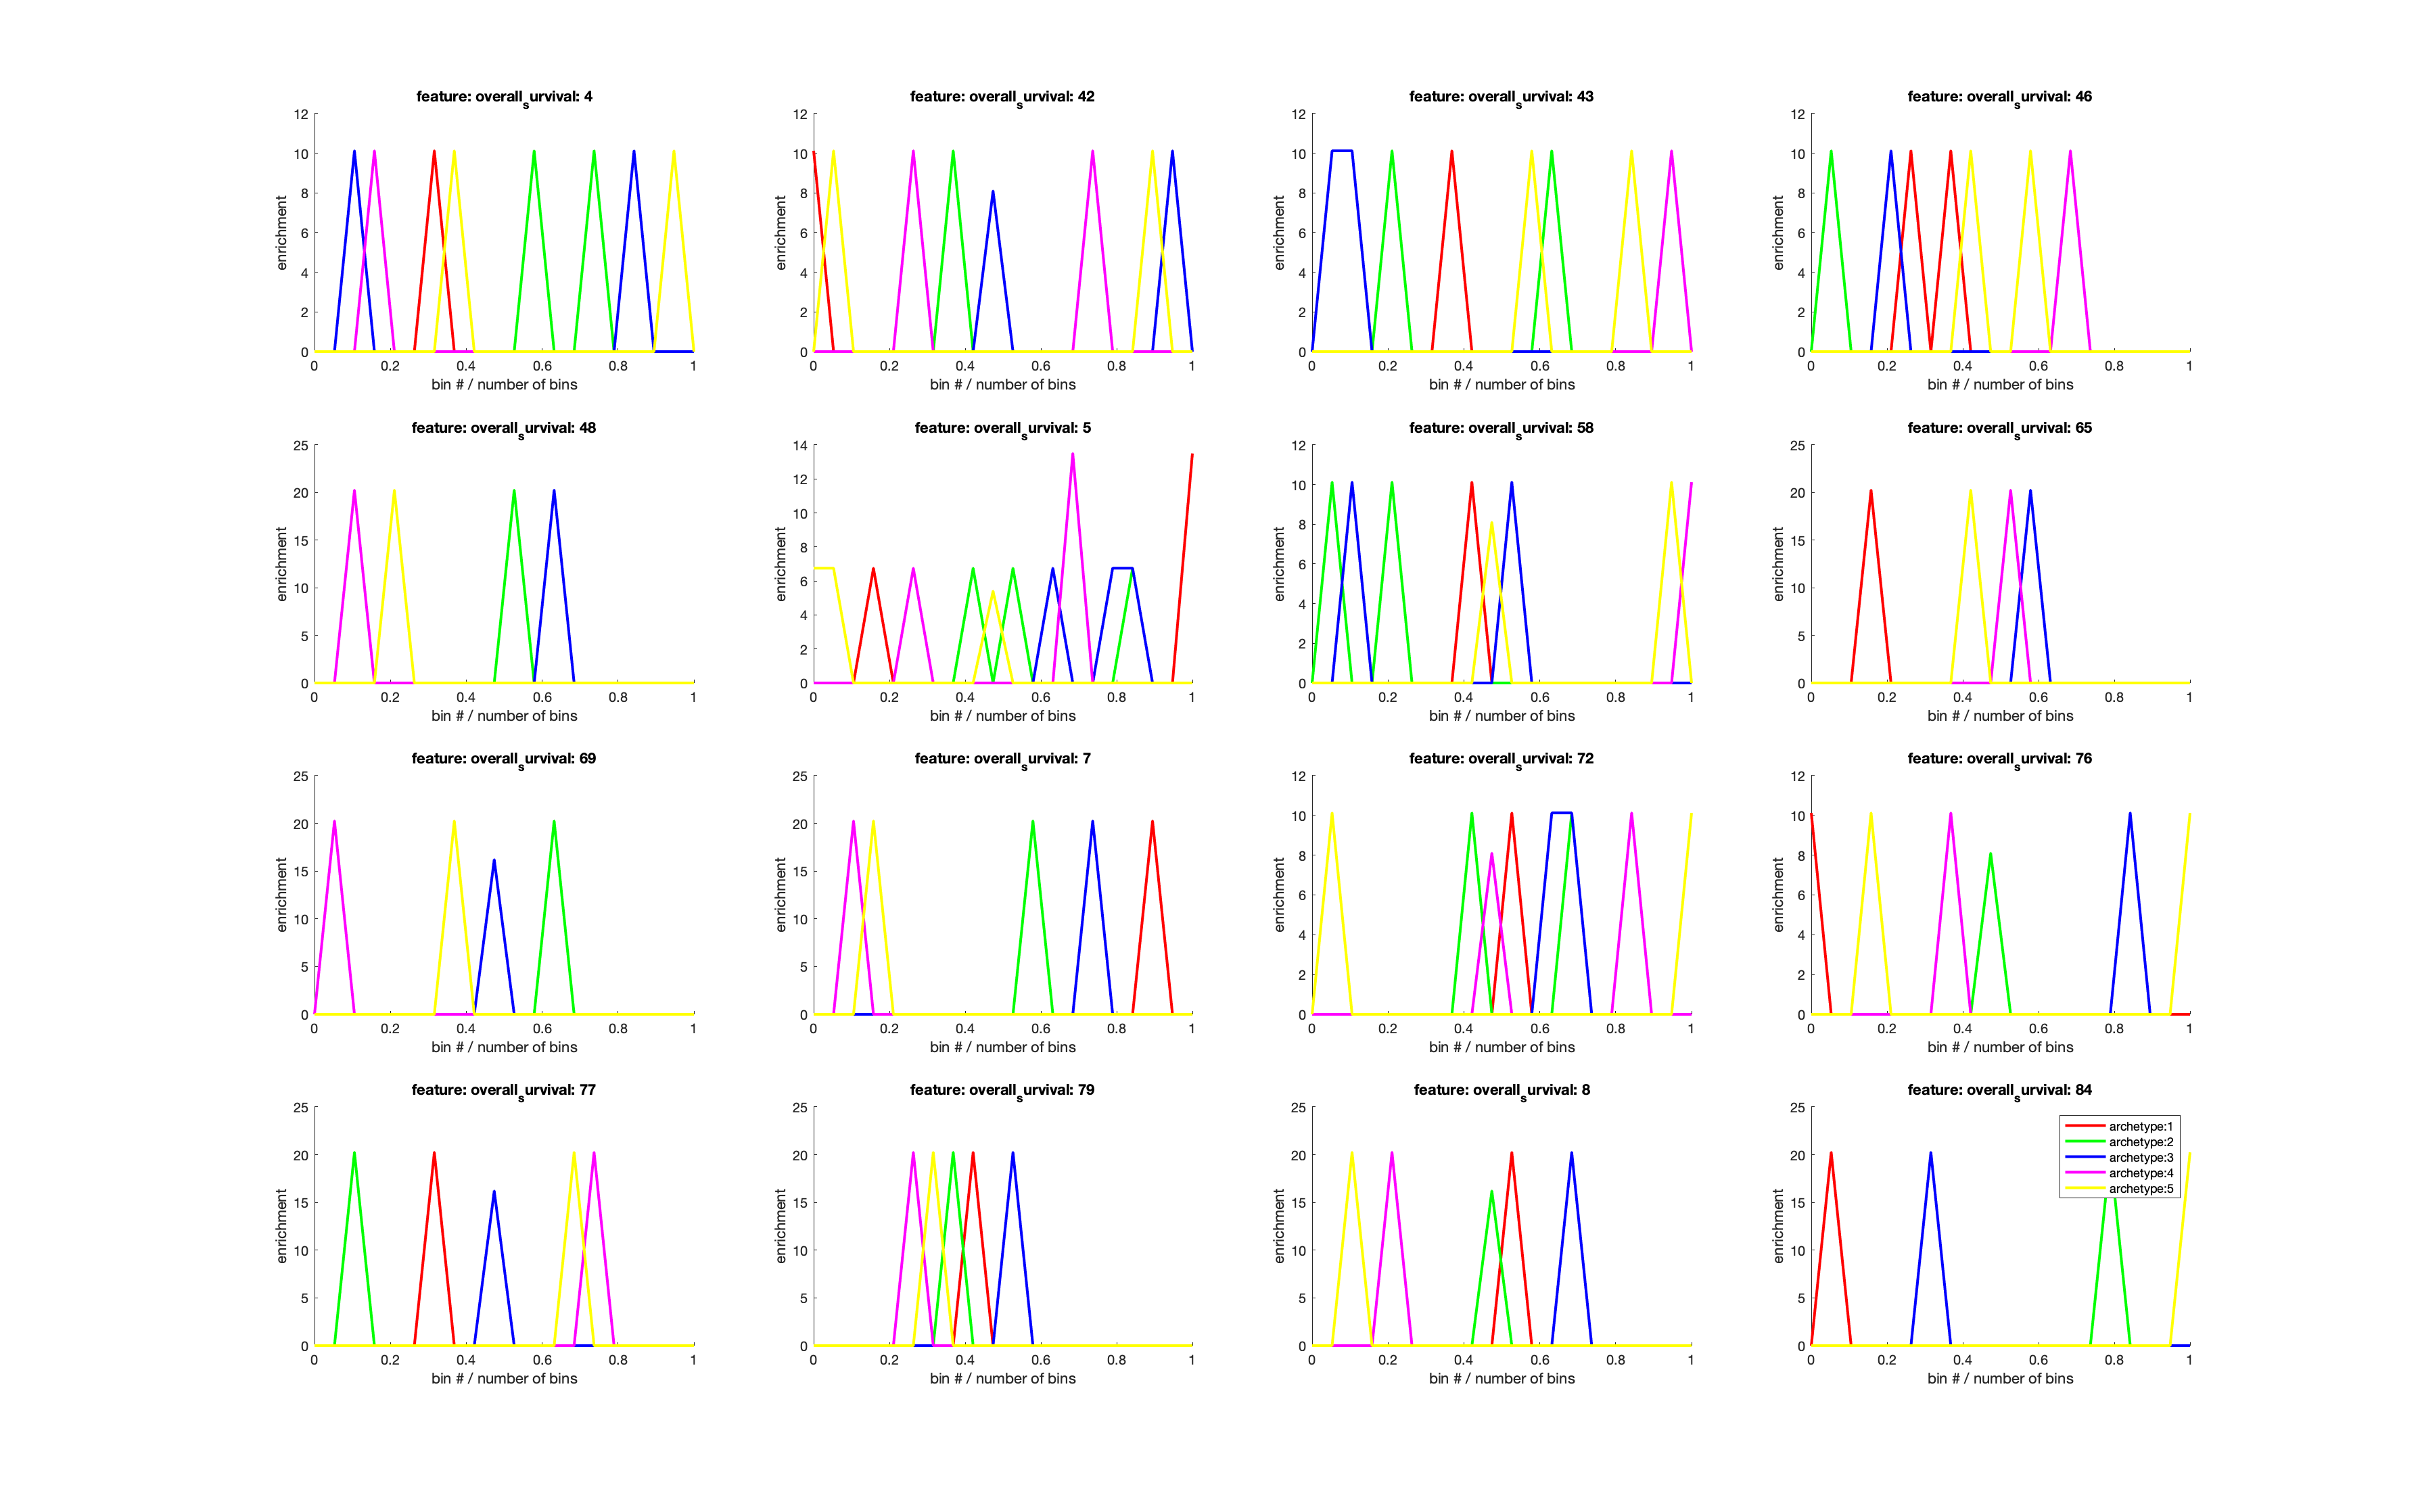

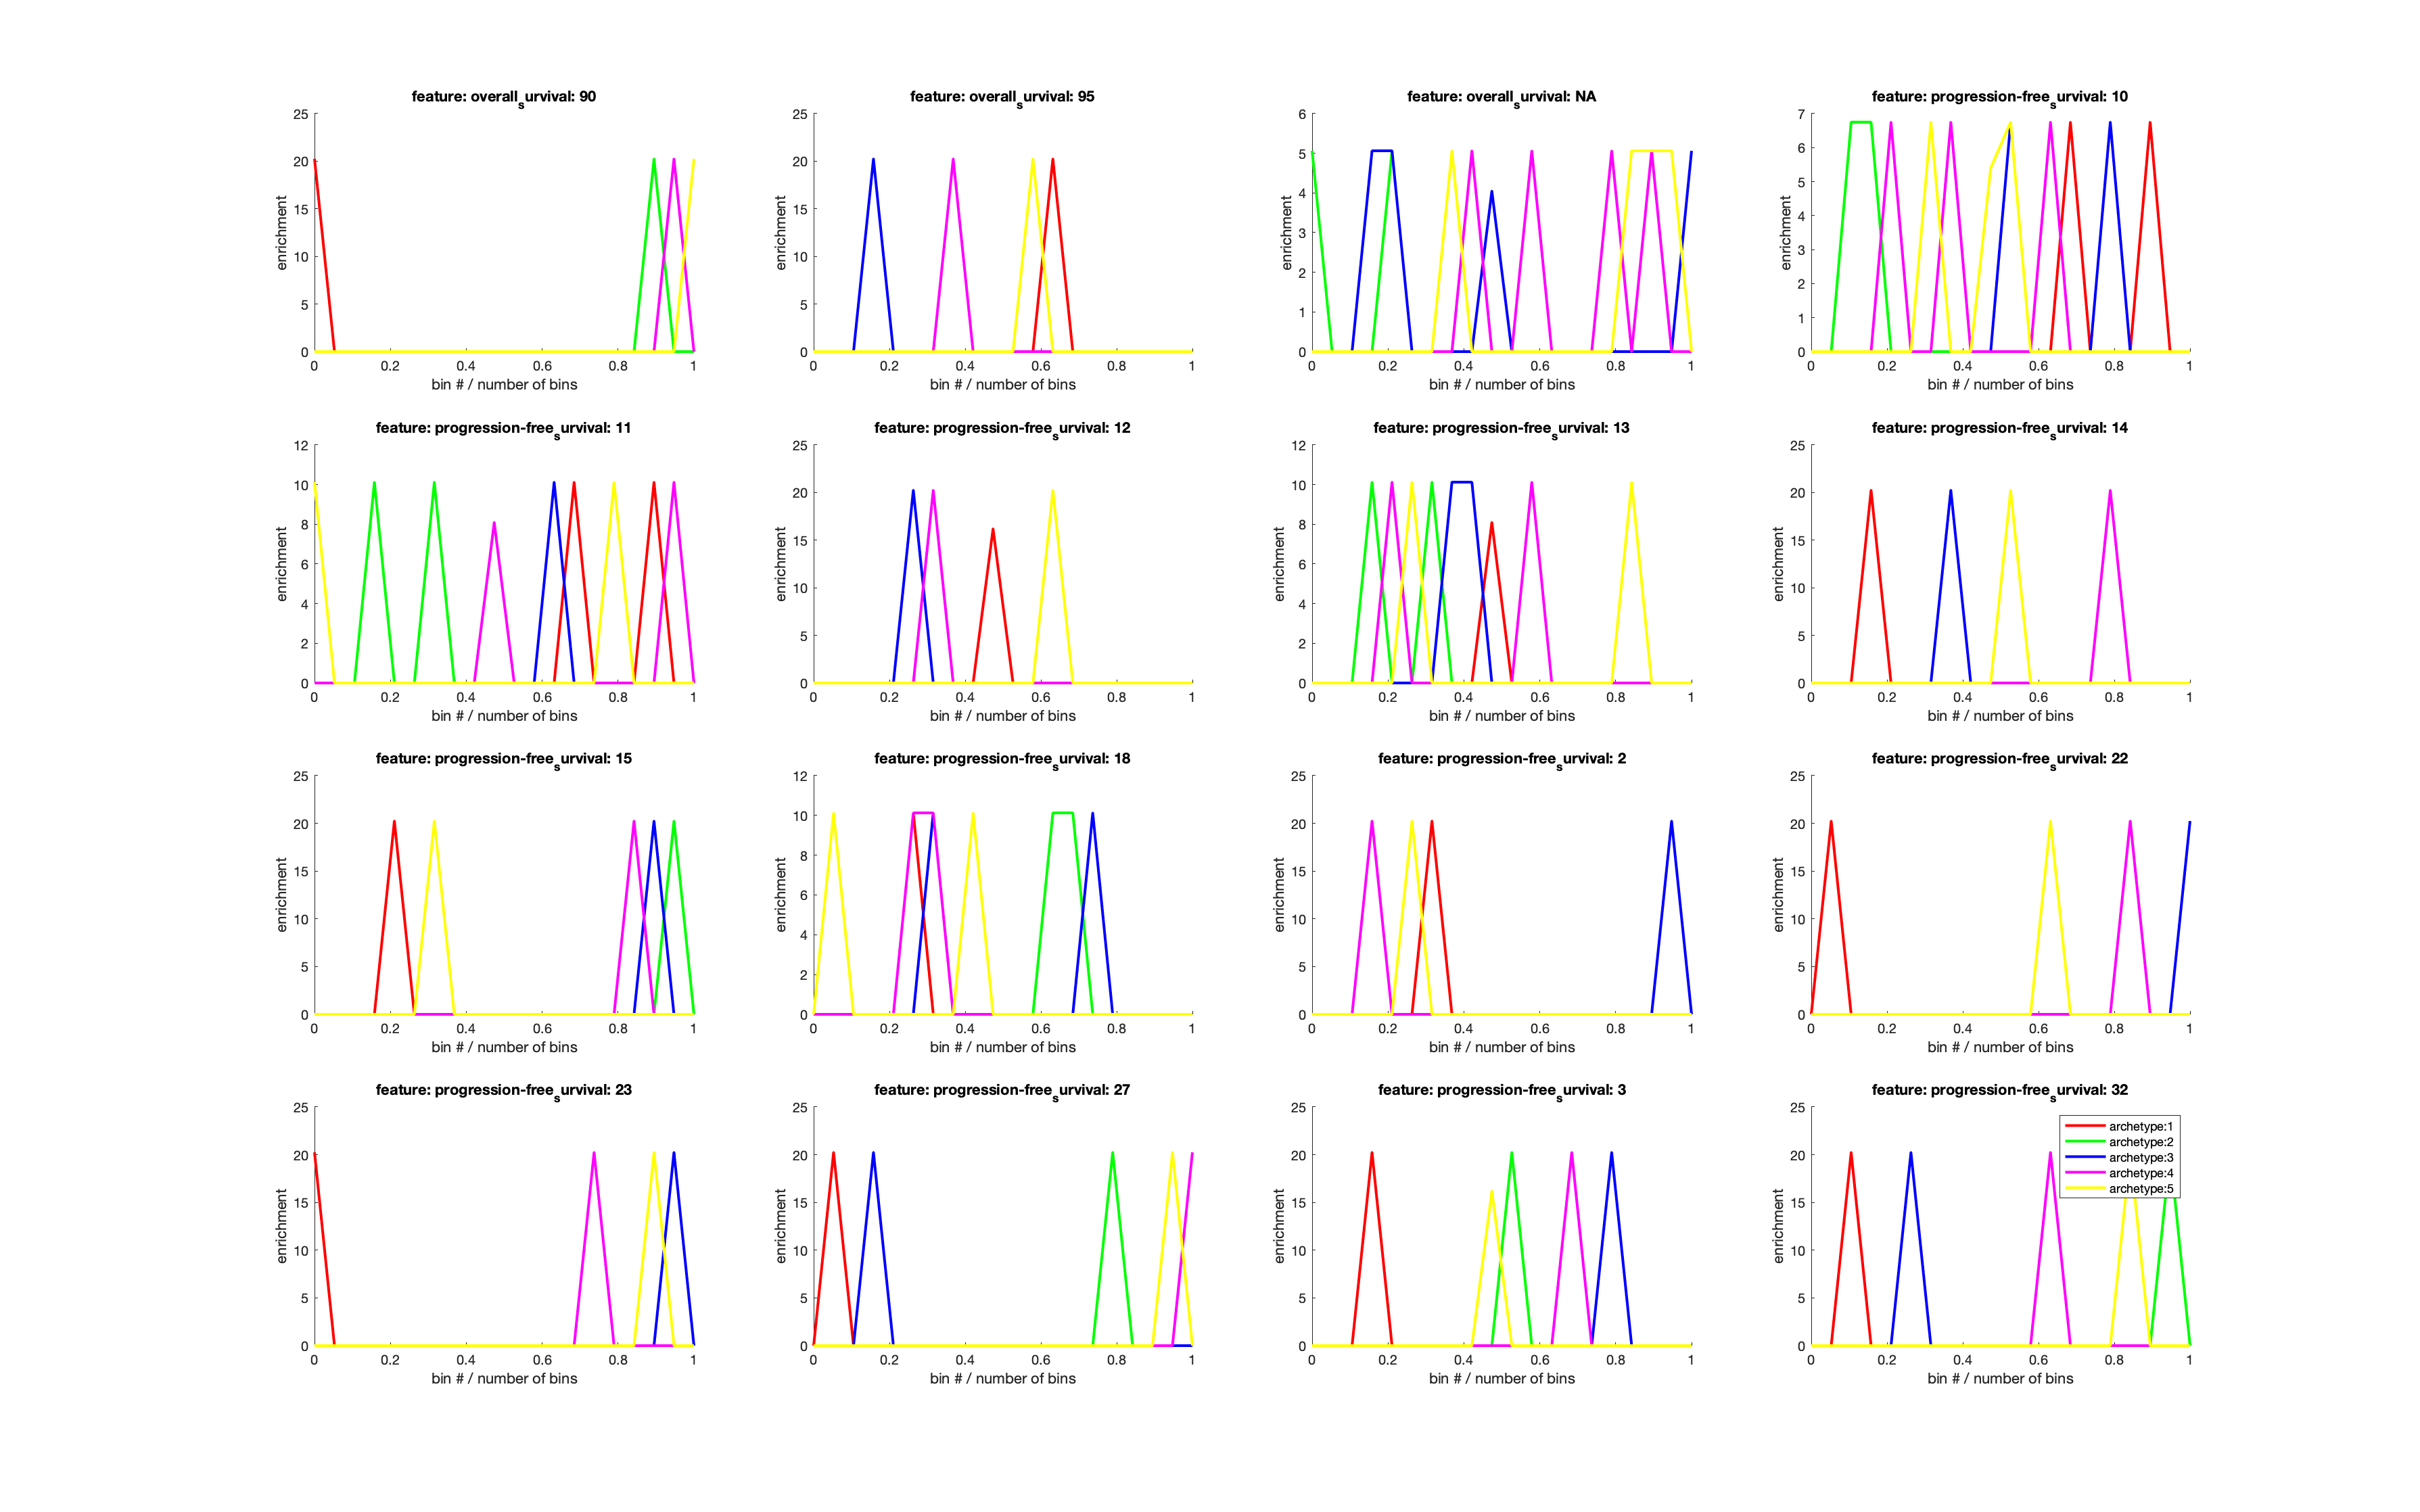

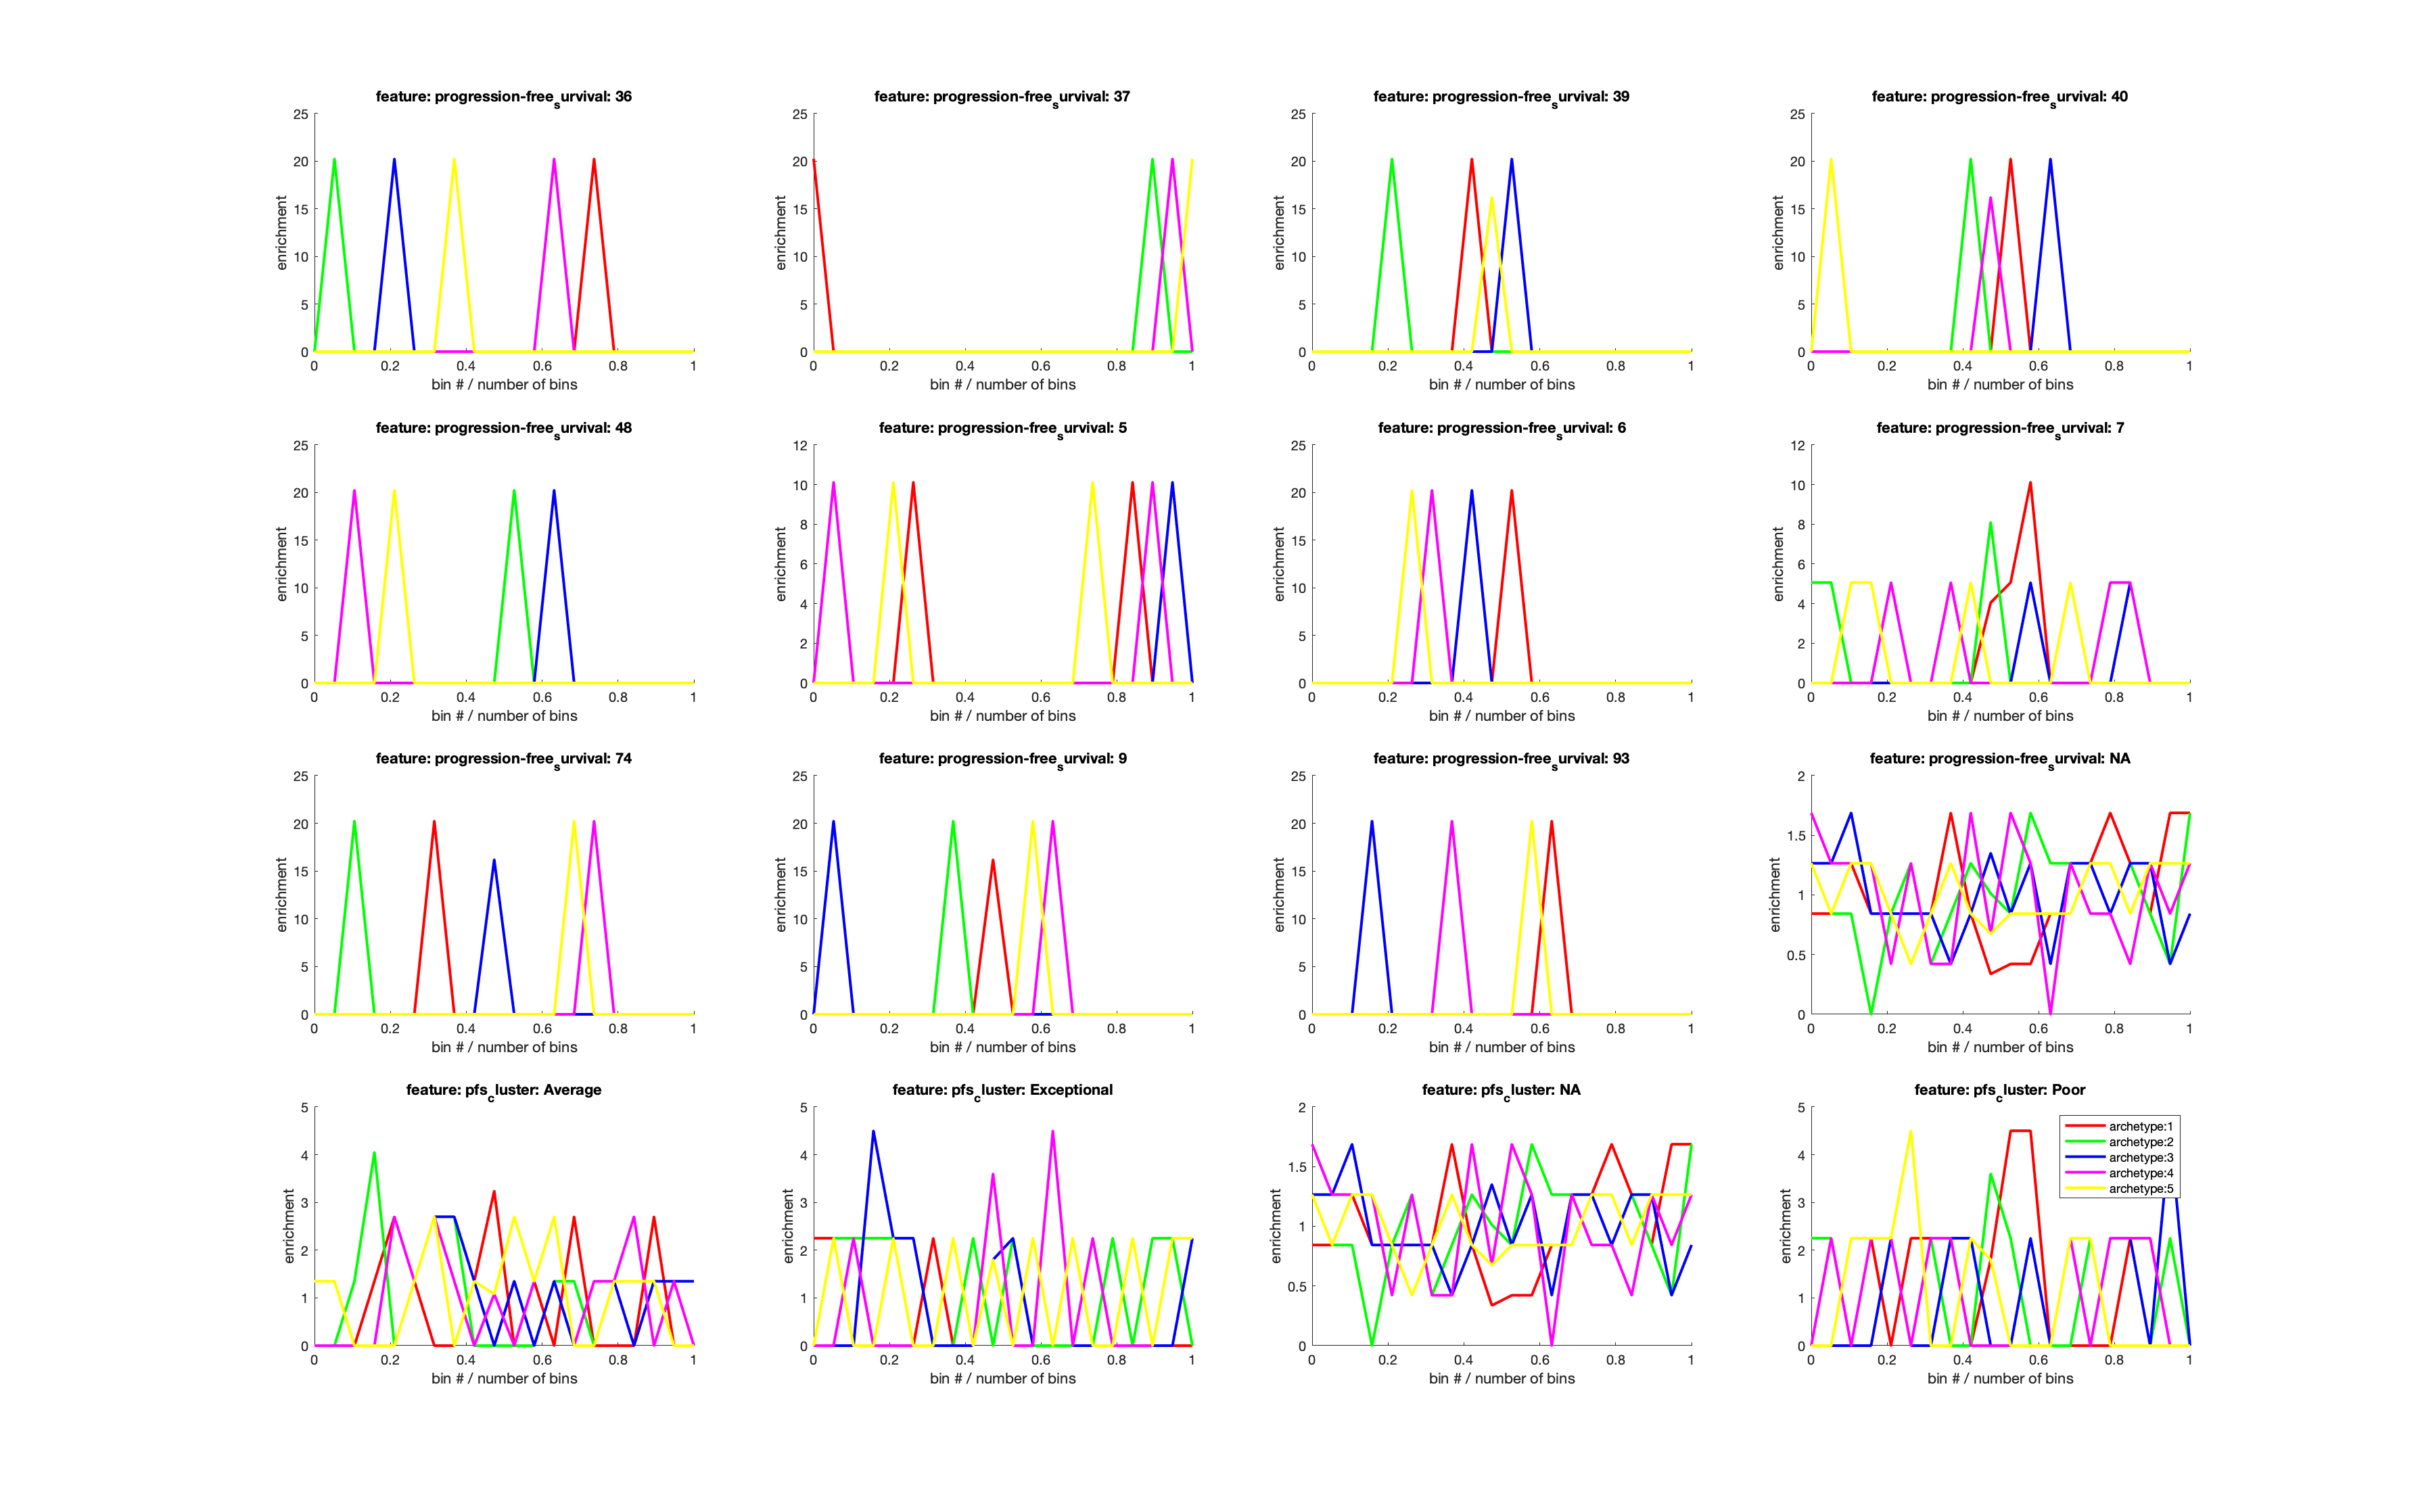

Finished computing discrete enrichments.
Finished computing continuous enrichments.
*** Wrote summary of enriched discrete features to ParTIoutputFile_discrete_significant.csv


[arc, arcFull, pc, errs, pval, coefs] = ParTI(geneExpression, 5, 12, discrAttrNames, ...
    discrAttr, 0,  'thomas_tumors');

### Random permutation for PCA/ESV comparison

Converting discrete features to booleans
Error - number of columns of Enriched should match number of category-names
Starting to perform PCA, for big data on slow computers this may take a while...


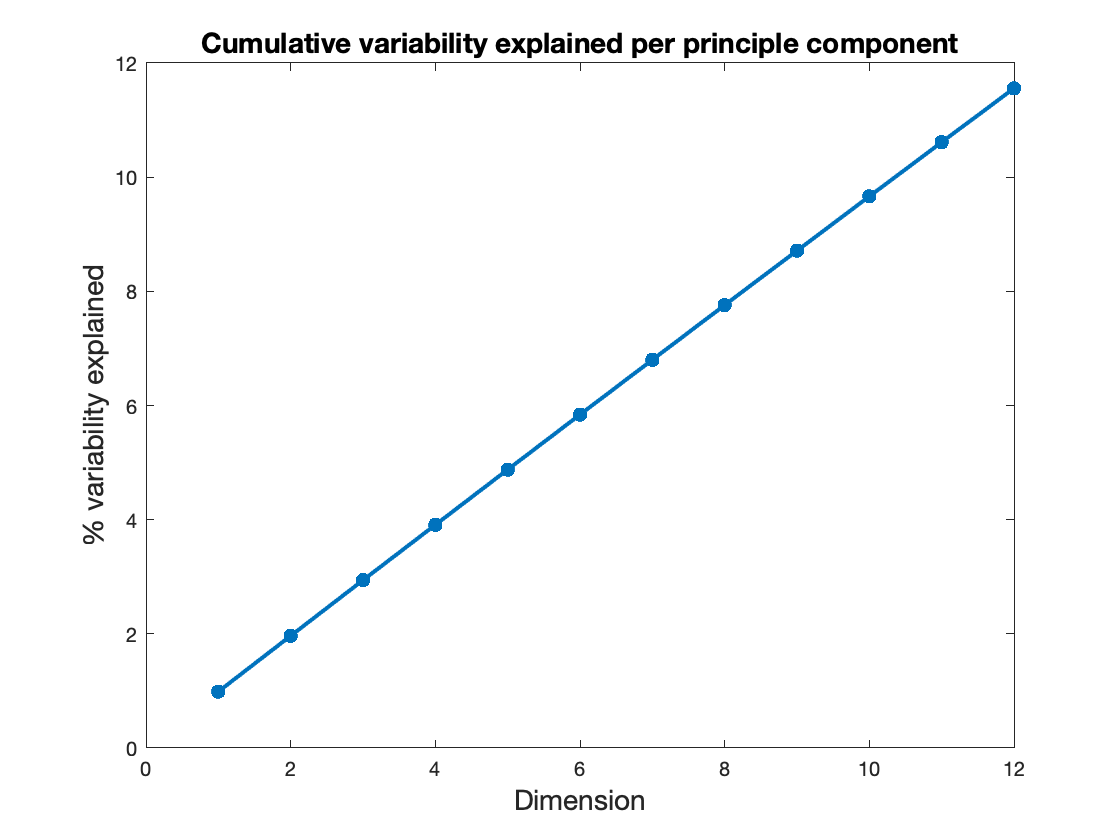

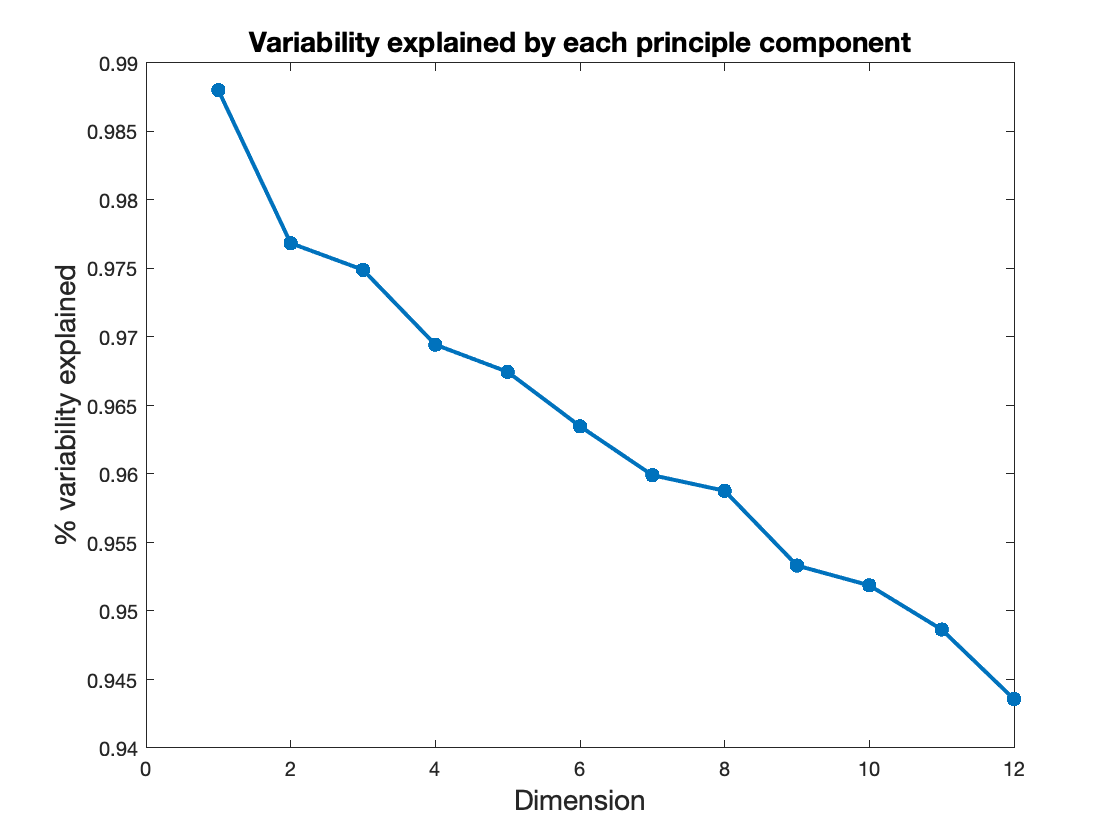

Calculating explained variance with PCHA (Morup M, Hansen KL, 2011)


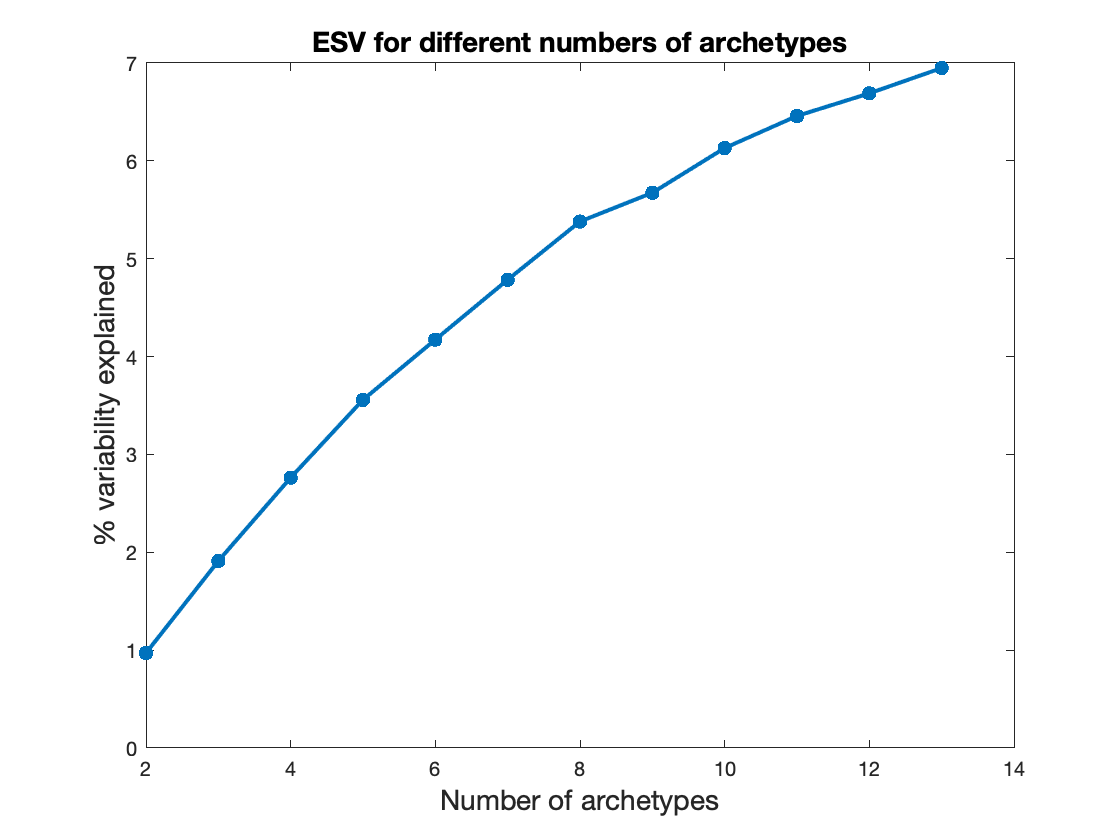

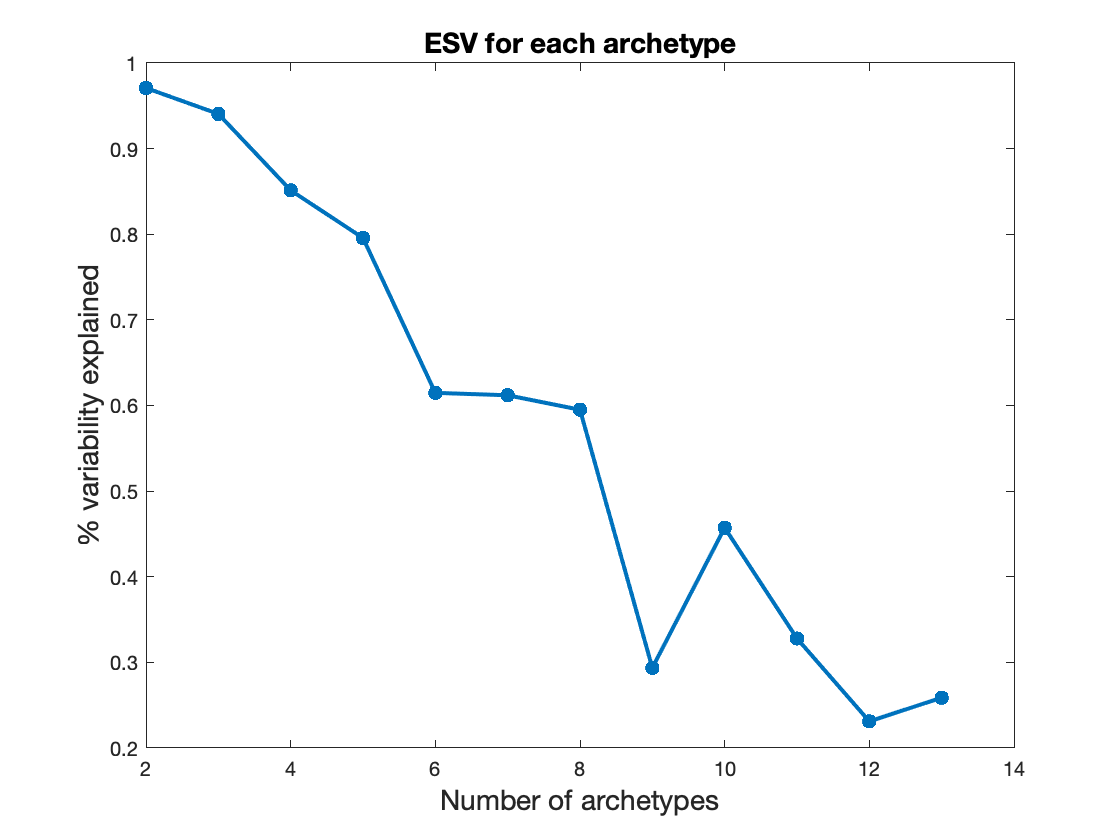

Calculating archetypes positions with PCHA (Morup M & Hansen LK, 2011)
finished finding the archetypes


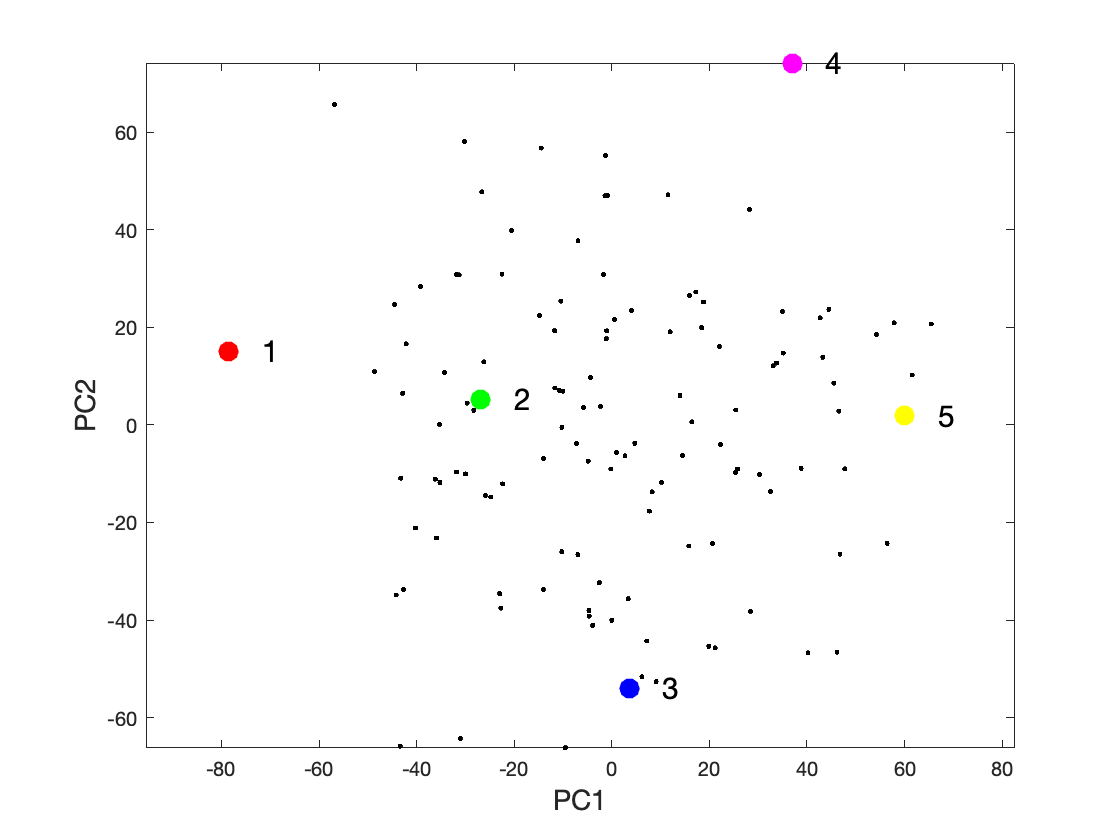

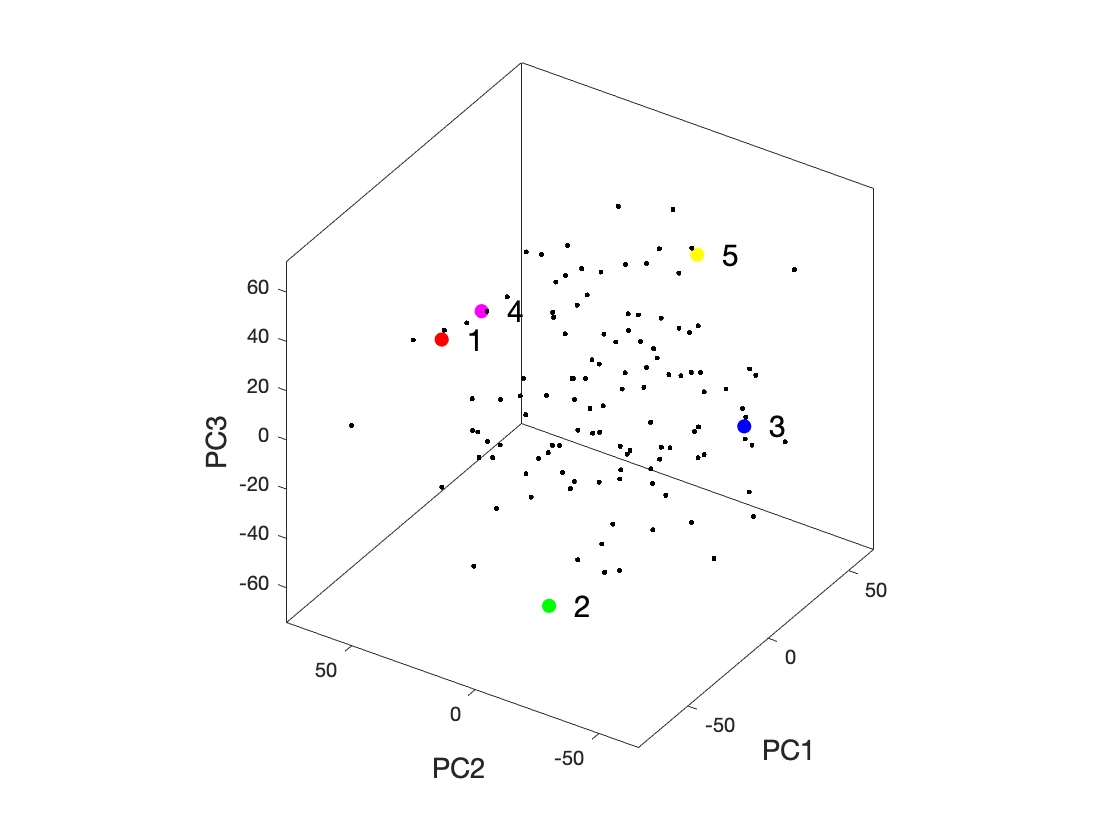

Finished sorting data points.
Finished computing discrete enrichments.
Finished computing continuous enrichments.


X=randperm(numel(geneExpression));
ShuffledData=reshape(geneExpression(X),size(geneExpression));
[rand_arc, rand_arcFinal, rand_pc_lite] = ParTI_lite(ShuffledData, 5, 12, 0.1, 'random');